데이타 읽어 들이기.

%['C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-05-12_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-06-30_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2018-04-12_batchdata_updated_struct_errorcorrect.mat']

clear ;
close all;

batchNum = 1;
load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

기본 데이타 분석

i=3 

i = 3

policy = trainData(i).policy 

policy = '3_6C-80PER_3_6C'

policy_readable = trainData(i).policy_readable 

policy_readable = '3.6C(80%)-3.6C'

channel_id = trainData(i).channel_id

channel_id = "3"

cycle_life = trainData(i).cycle_life

cycle_life = 1177

chargetime = trainData(i).summary.chargetime

chargetime =          0
   13.3414
   13.3415
   13.4258
   13.3412
   13.3413
   13.4257
   13.4256
   13.3414
   13.3413


cycle = trainData(i).summary.cycle

cycle =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


IR = trainData(i).summary.IR

IR =          0
    0.0169
    0.0168
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167


QCharge = trainData(i).summary.QCharge

QCharge =          0
    1.0798
    1.0811
    1.0819
    1.0825
    1.0828
    1.0831
    1.0834
    1.0835
    1.0836


QDischarge = trainData(i).summary.QDischarge

QDischarge =          0
    1.0799
    1.0813
    1.0822
    1.0827
    1.0830
    1.0833
    1.0837
    1.0837
    1.0838


Vdlin = trainData(i).Vdlin

Vdlin =     3.5000
    3.4985
    3.4970
    3.4955
    3.4940
    3.4925
    3.4910
    3.4895
    3.4880
    3.4865


trainData(i).Vdlin

ans =     3.5000
    3.4985
    3.4970
    3.4955
    3.4940
    3.4925
    3.4910
    3.4895
    3.4880
    3.4865


cycleNum = 2

cycleNum = 2

cycleNum1 = 100

cycleNum1 = 100

size ( trainData(3).cycles(2).t )

ans =         1124           1


trainData(3).cycles(2).t 

ans =          0
    0.0025
    0.0029
    0.0032
    0.0036
    0.0040
    0.0043
    0.0045
    0.0048
    0.0051


% trainData(3).cycles(1).t(2:3,:)
 
trainData(3).cycles(cycleNum).t 

ans =          0
    0.0025
    0.0029
    0.0032
    0.0036
    0.0040
    0.0043
    0.0045
    0.0048
    0.0051


# 그래프로 확인

# 전체 전류 ( 충/방전 )

#### 테스트 환경 설정

test_bat = 6 ;
cycle_div = 500;

# 측정 포인트 대비 시간 - 1:1 이 아니다.

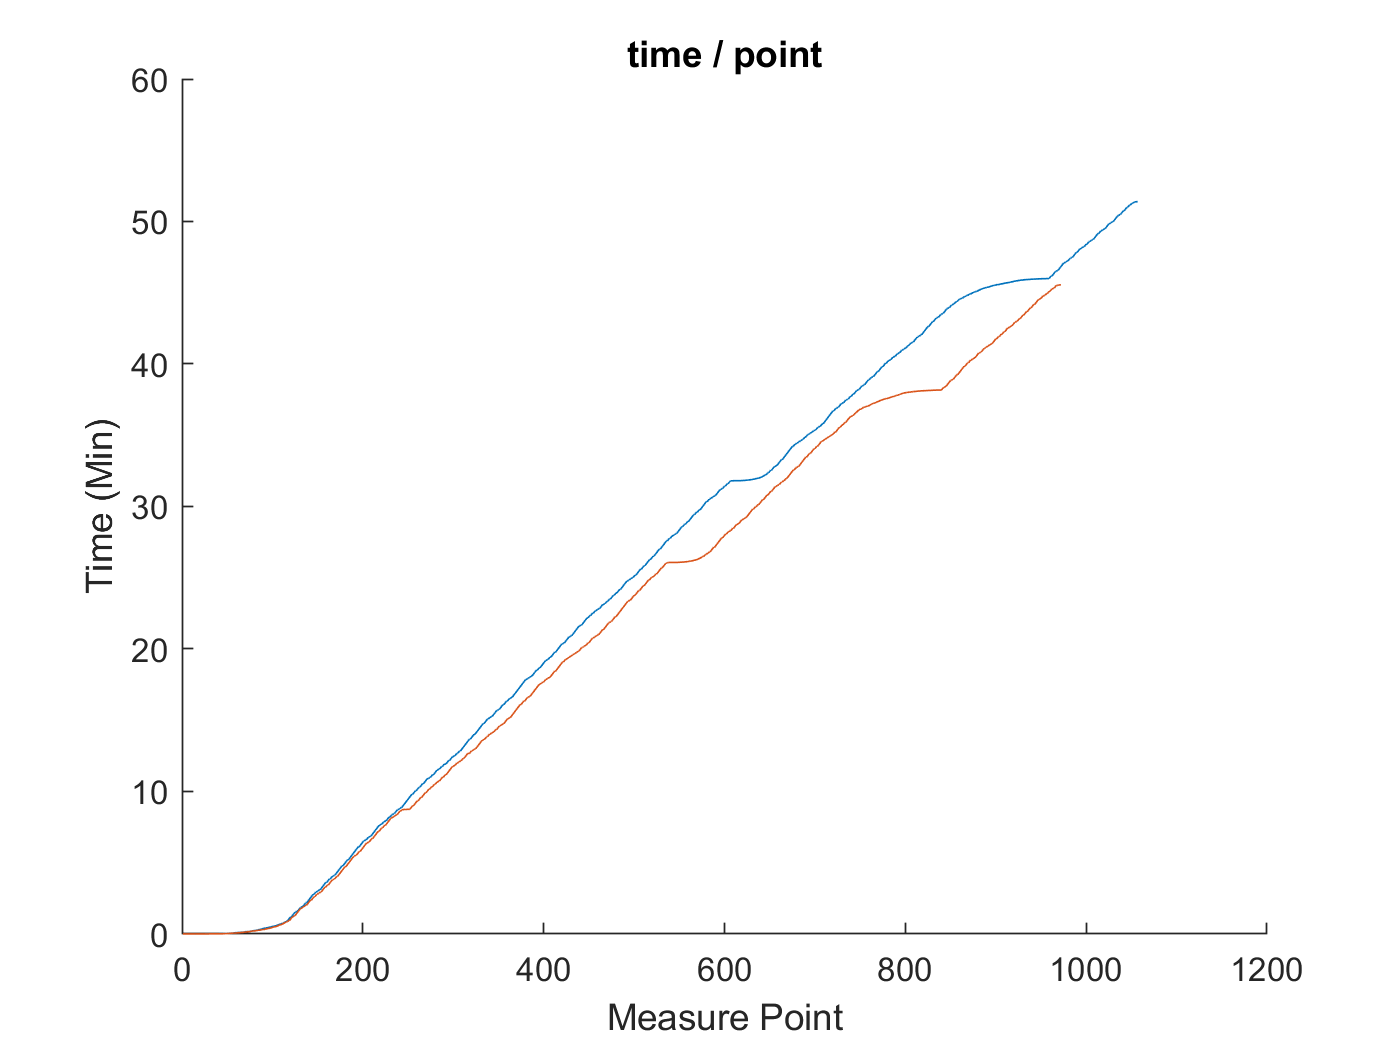

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t)
    end
end
hold off , xlabel 'Measure Point' , ylabel 'Time (Min)' , title 'time / point'

#### Charge Q / Meature Point

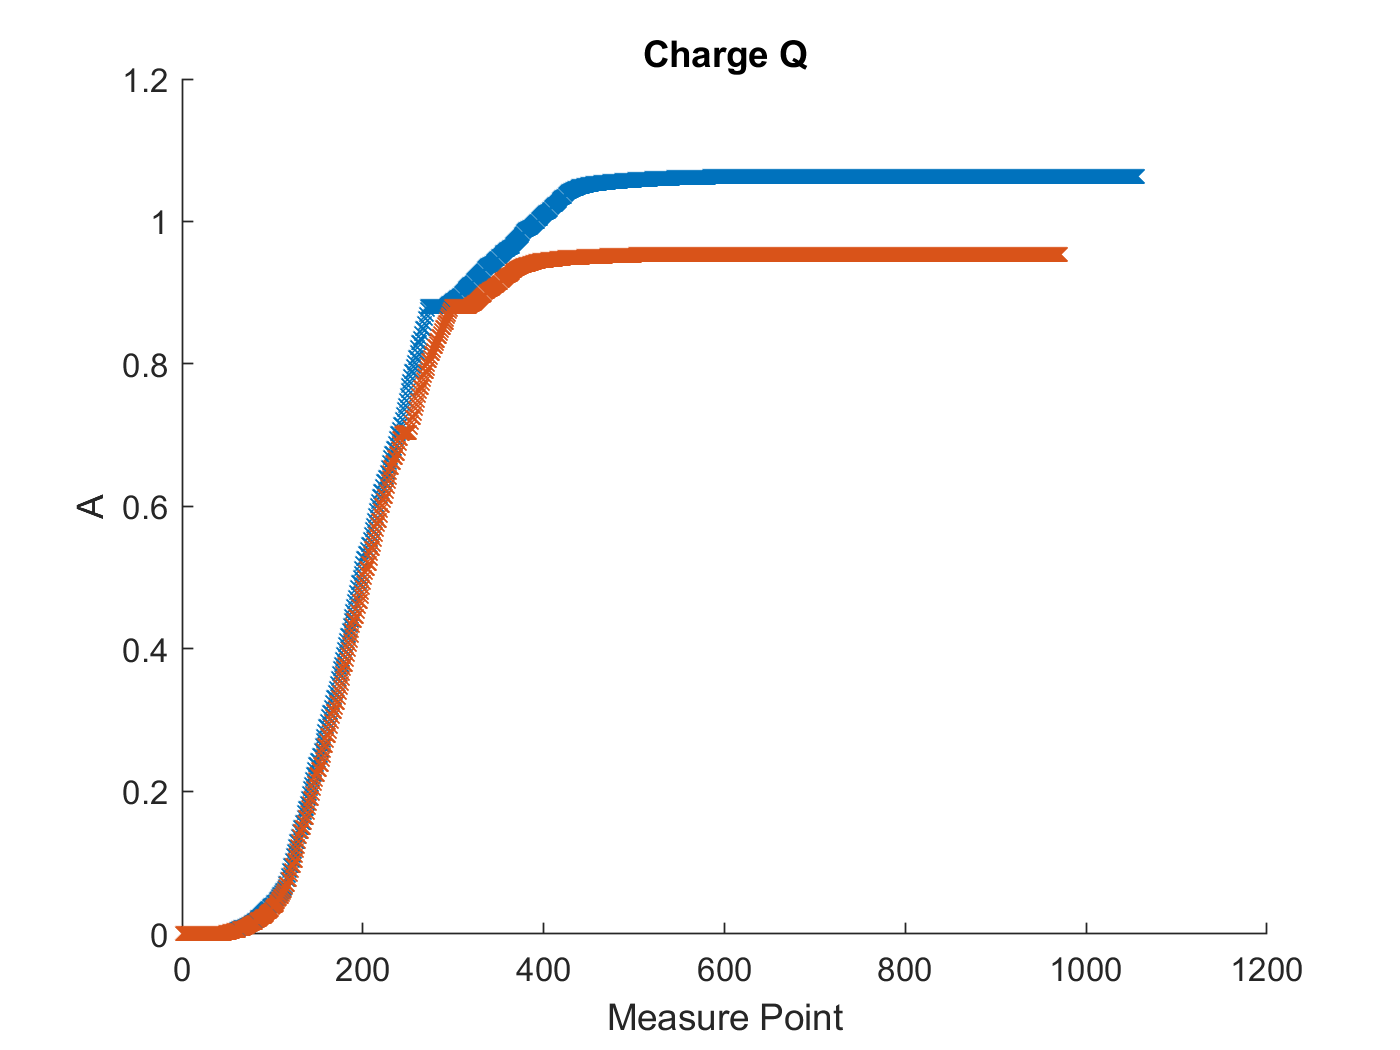


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,'x')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Q'

#### Charge Q / Time

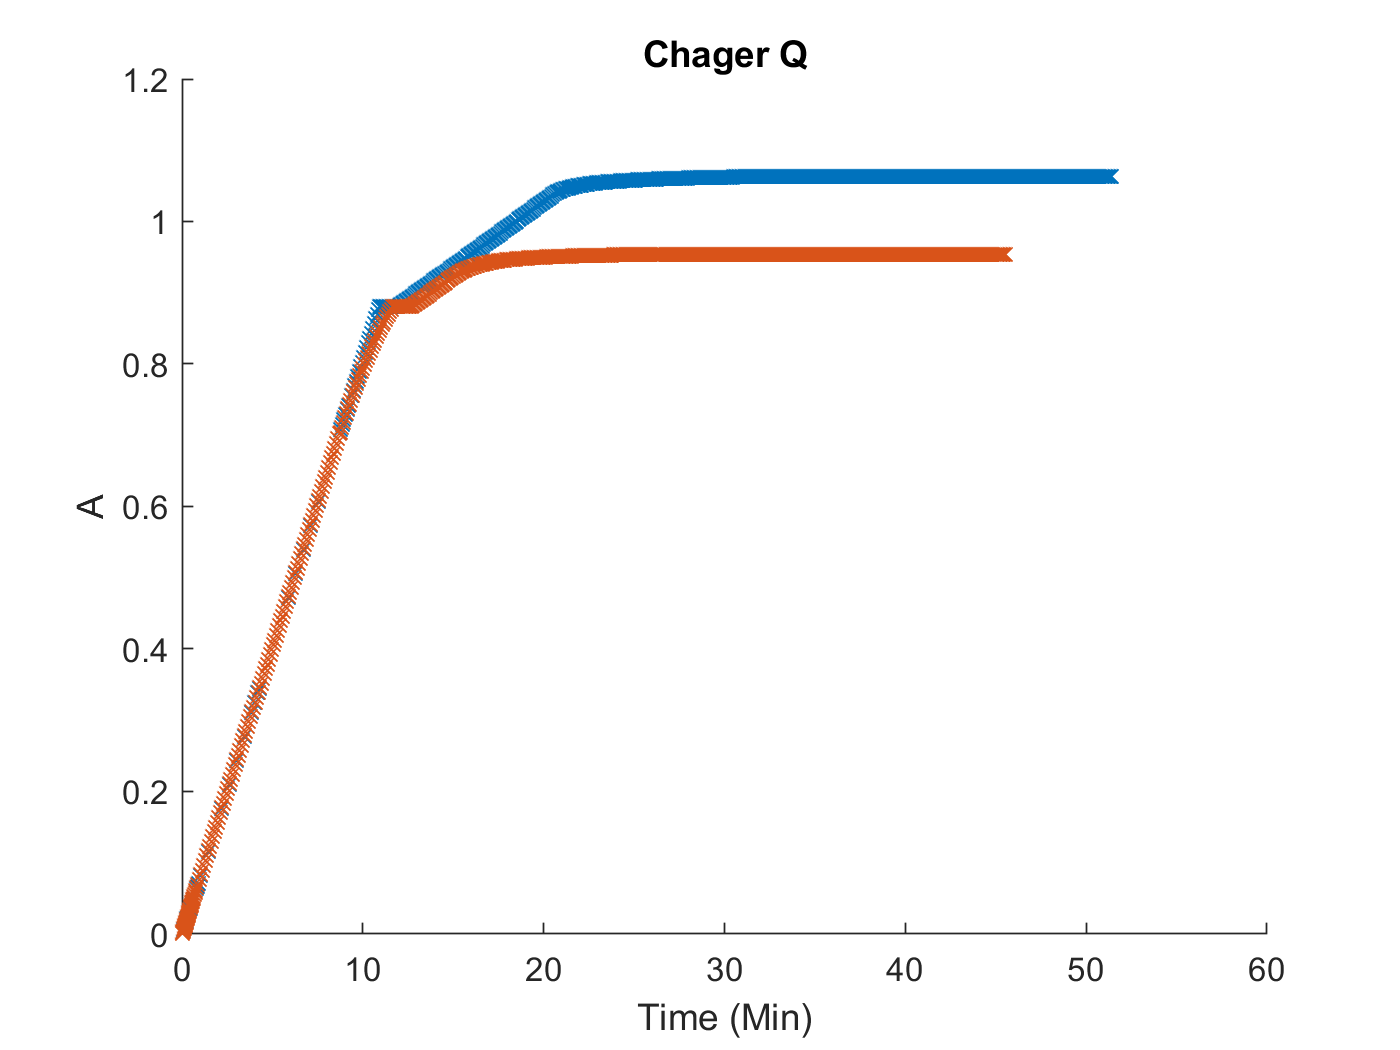

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Chager Q'

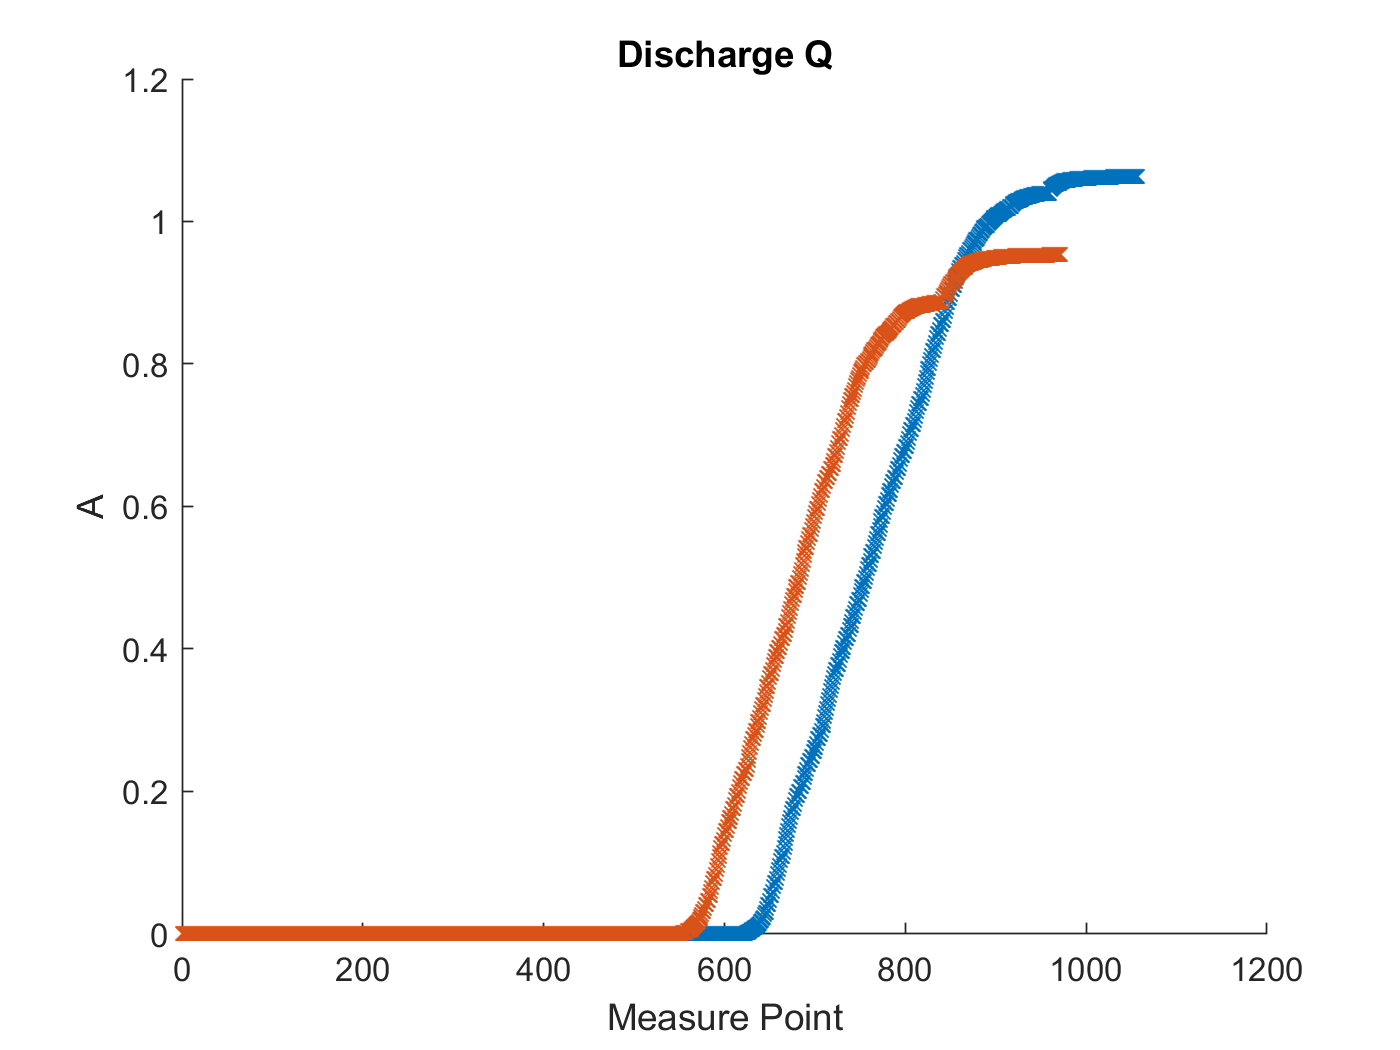

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,'x')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Discharge Q'

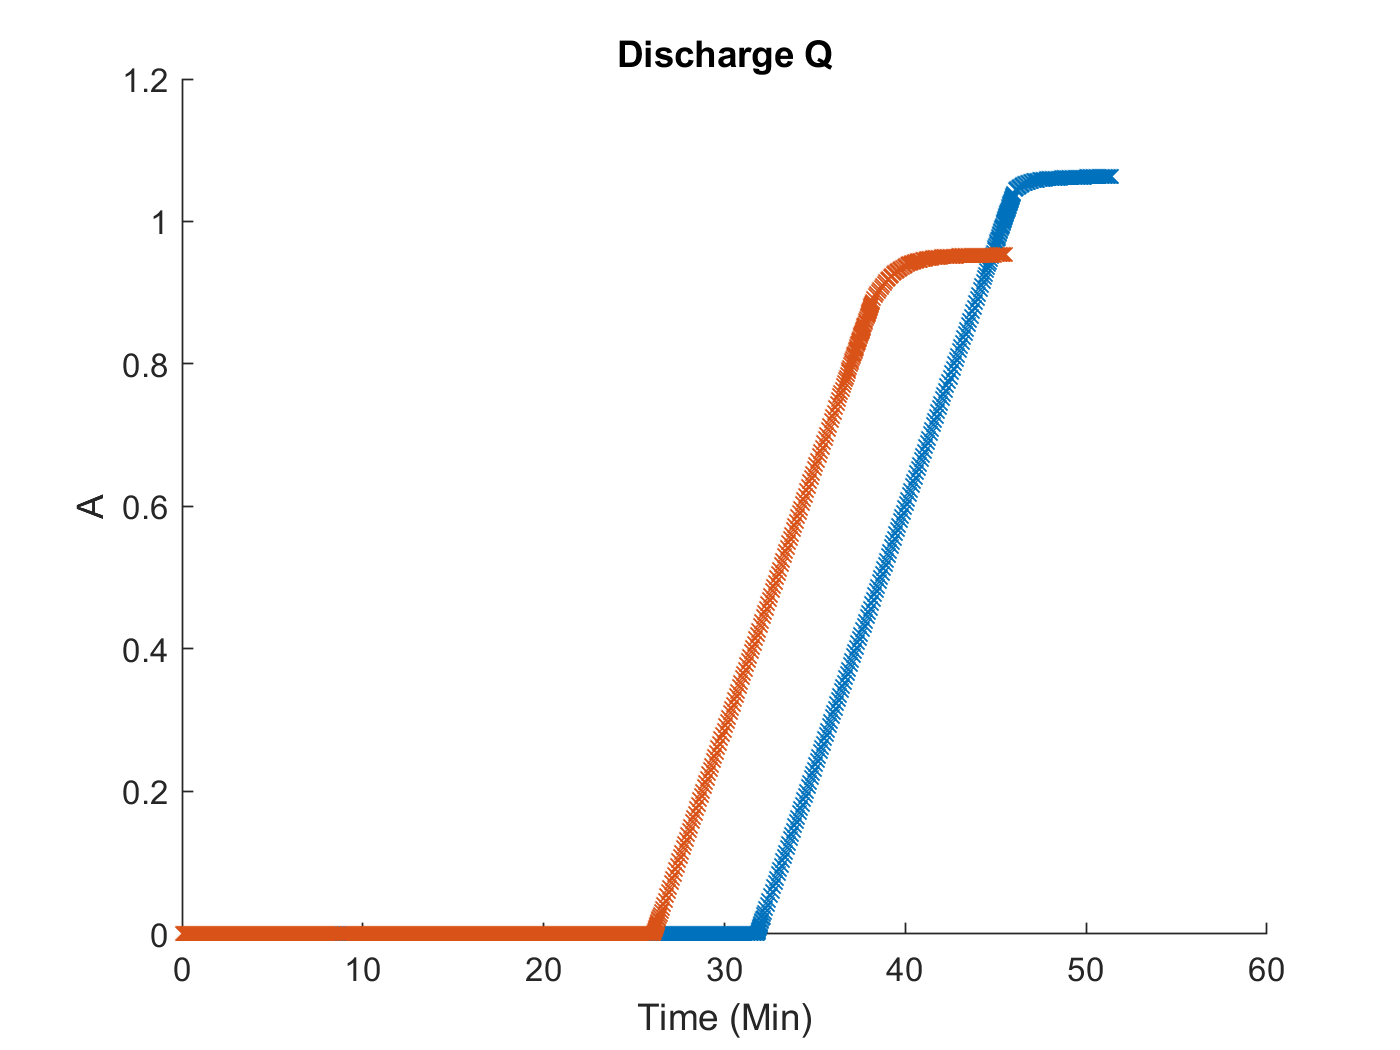


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'x')
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Discharge Q'

#### Qc 와 Qd 를 보면 이를 통해 충전 사이클과 방전 사이클을 확인할 수 있다.

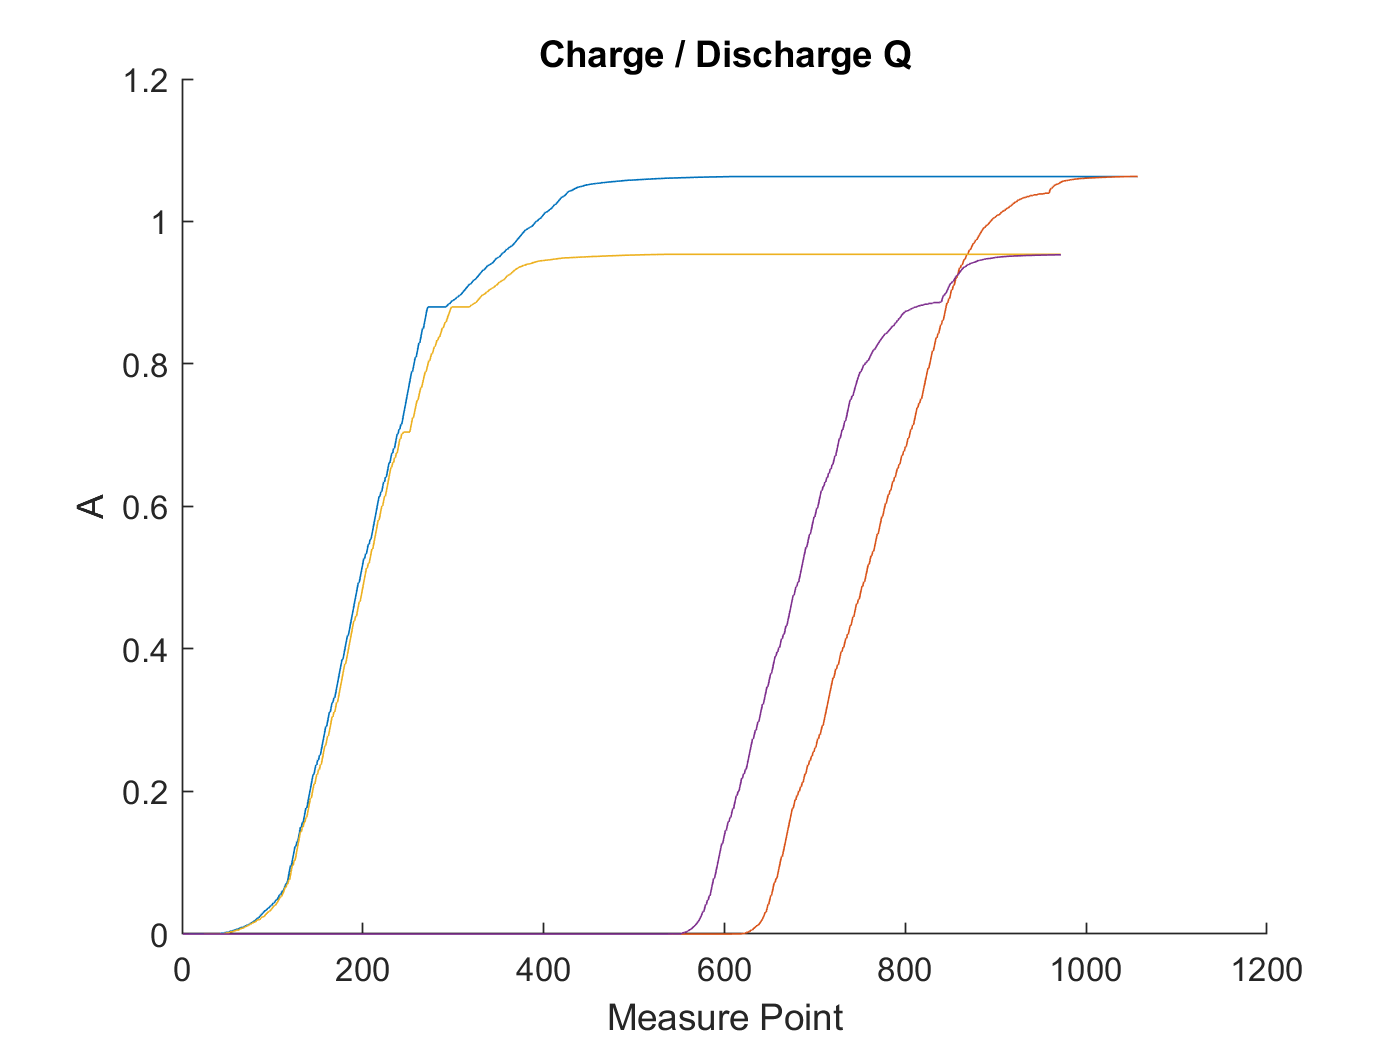

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc)
        plot(trainData(test_bat).cycles(i).Qd,'-')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge / Discharge Q'

# 충전 전류 분석

#### I는 충방전 전체 사이클에 대한 정보이다.

#### 충전시와 방전시로 분리하자.

#### Measure Point 는 Cycle 이 증가할 수로 줄어든다.

#### Measure Time 는 Cycle 이 증가할 수로 줄어든다.

#### x 축의 마지막 값이 cycle 에 따라 달라지면 이를 이용하기 힘들다.

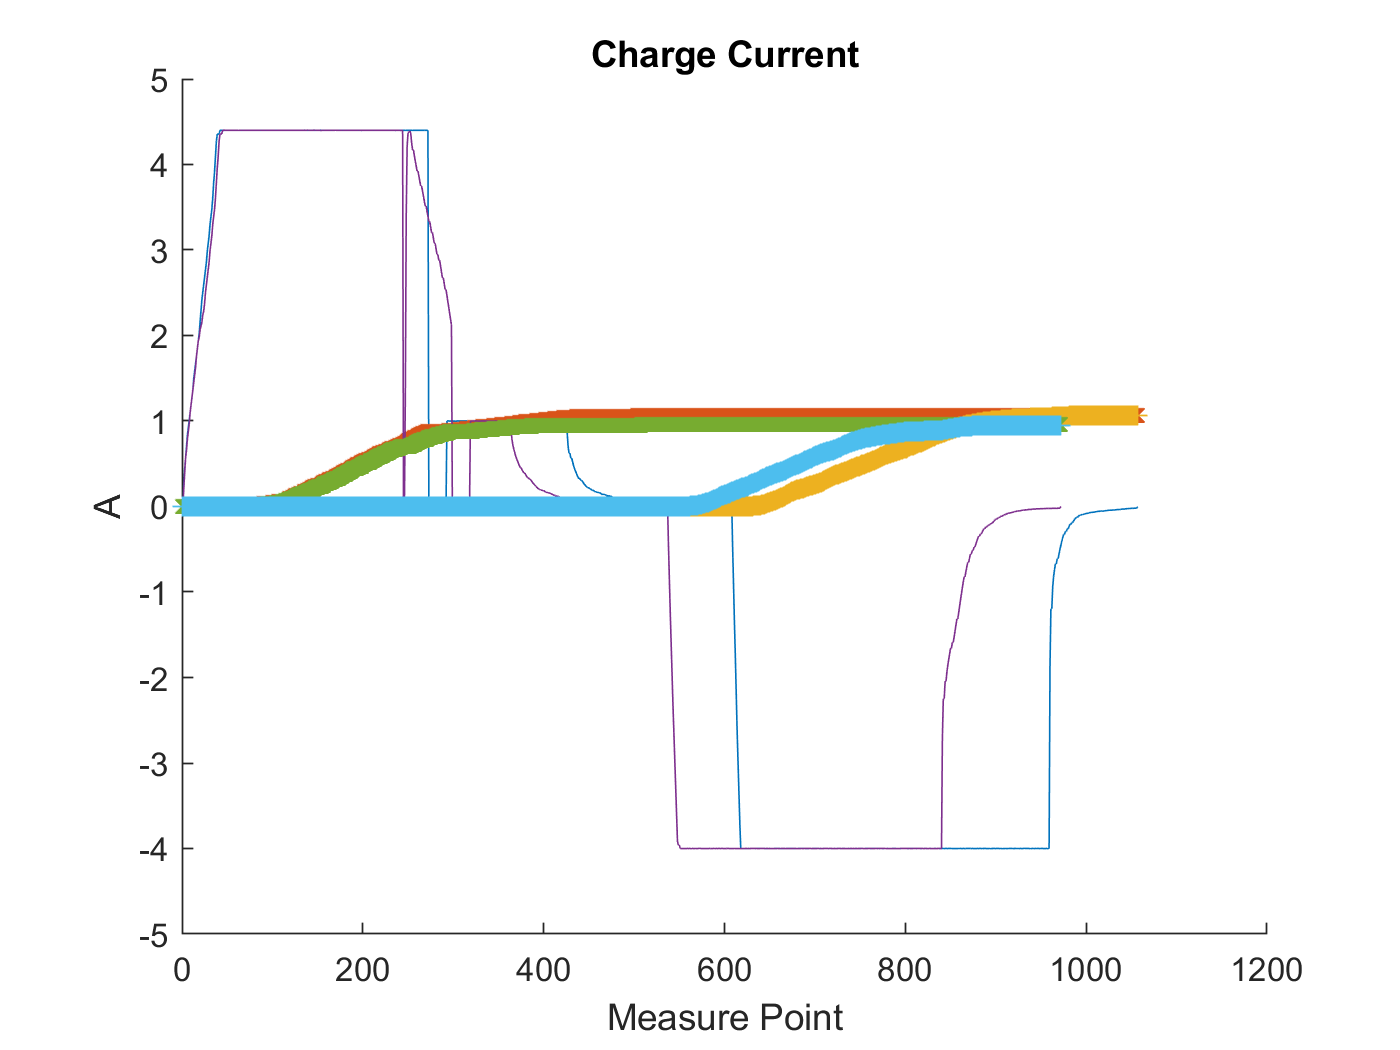

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).I)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Current'

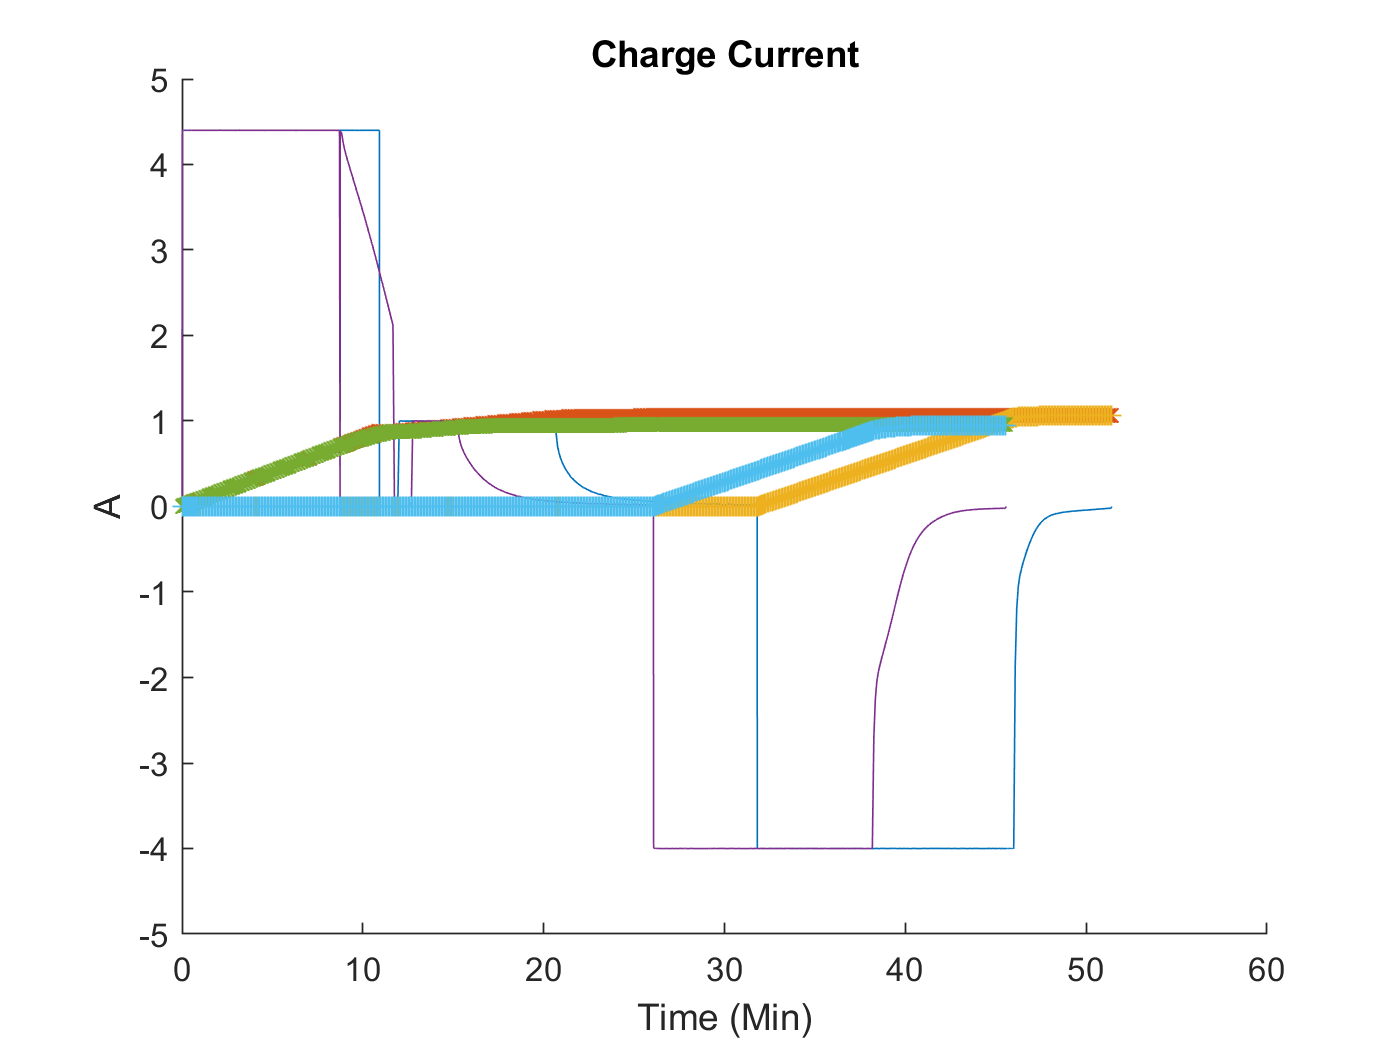

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).I)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Current'

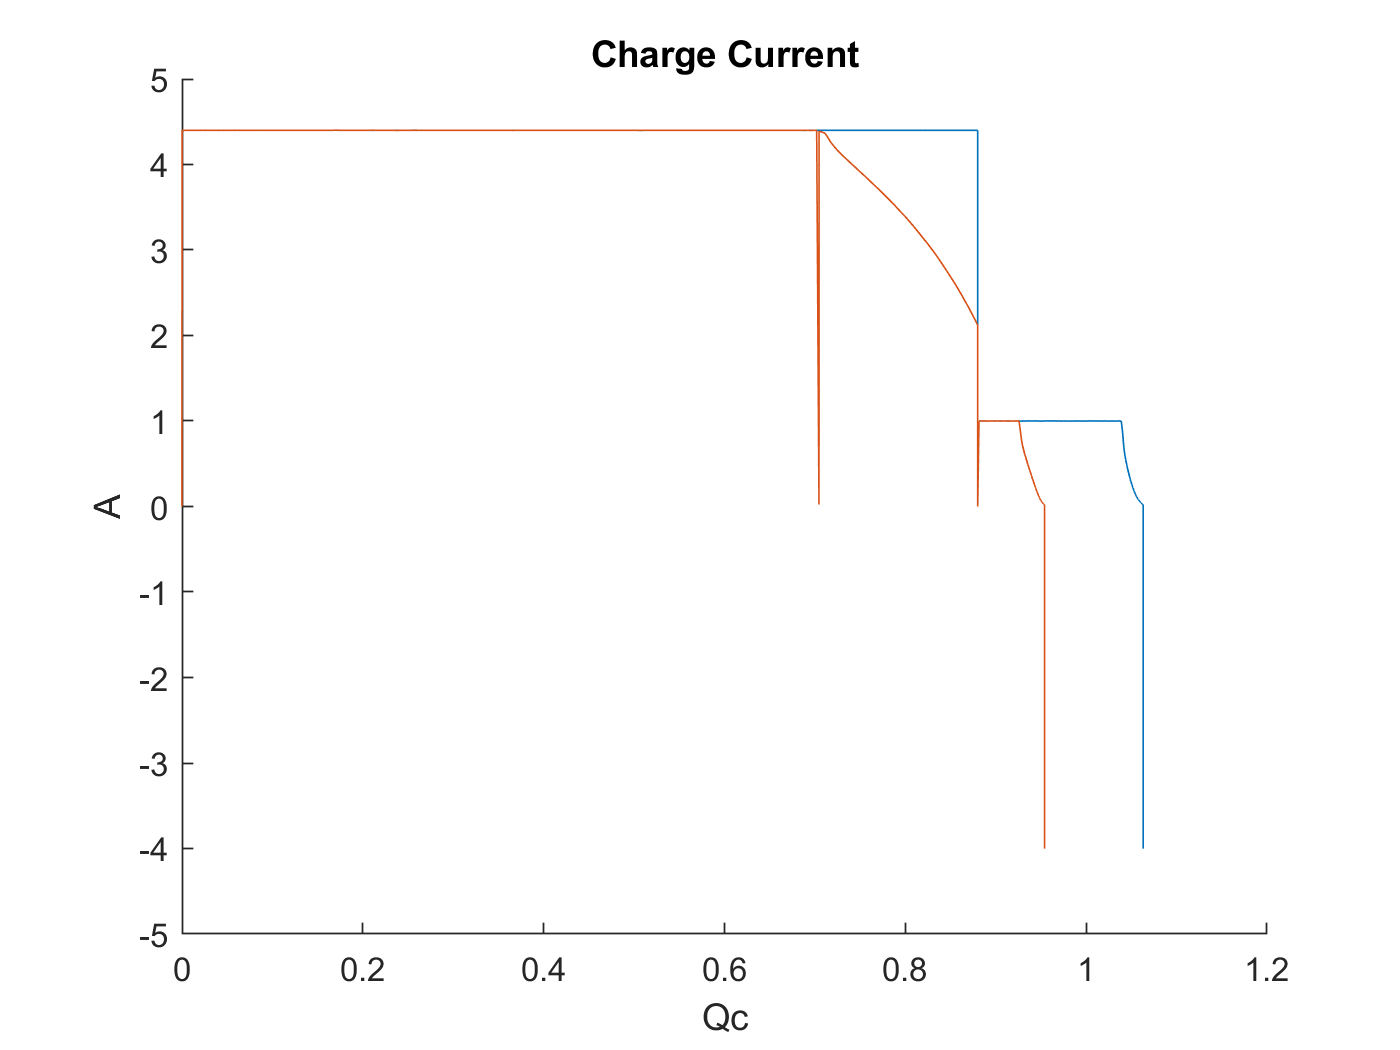


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).I)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'

#### 아래 그래프에서 이상치가 있어 smooth함수를 사용했지만 큰 개선은 없다.

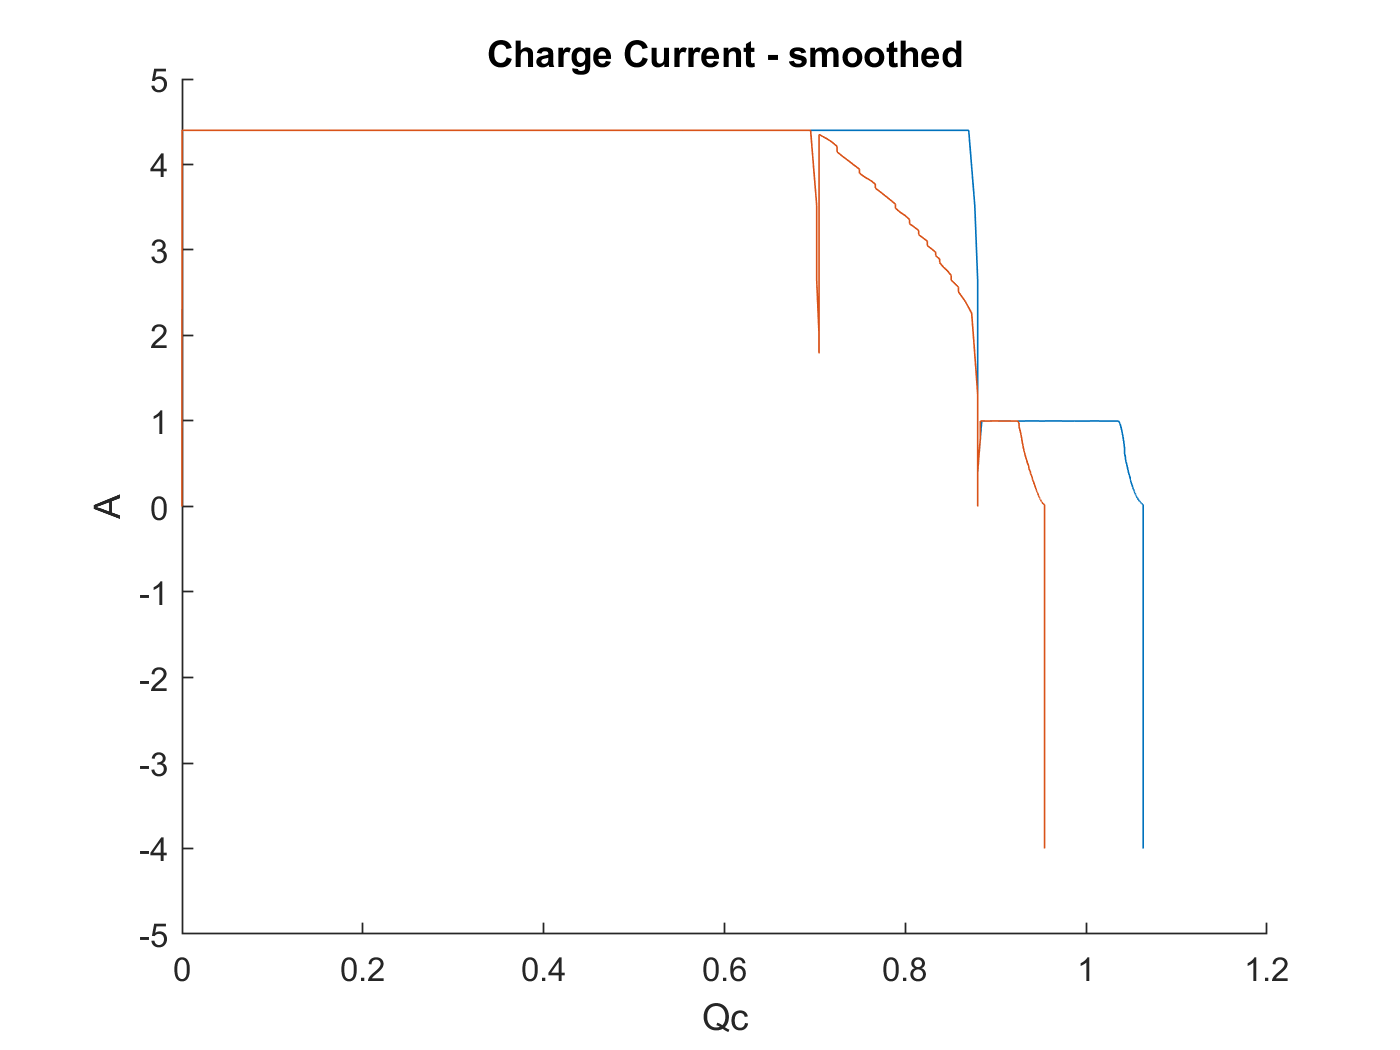

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,smooth(trainData(test_bat).cycles(i).I))     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current - smoothed'

#### x축의 단위를 용량기준으로 0 부터 1.2까지의 100개의 포인트로 전환하자. 

#### 변환에서 중요한 것은 Qc에 해당하는 I를 구하는 것이다.   

#### uniq함수에서  first 인자를 사용하면 동일한 용량값 여려개 있을때 첫번째를 선정하고

#### last 인자를 사용하면 동일한 용량값 여러개 있을대 제일 마지막 것을 선정한다.

#### 아래 그림에서 Ic를 얻기 위해서는 동일 Qc 의 첫번째 것을 선택해야 하고

#### Id를 얻기위해서는 Qd의 마지막 것을 선택해야 한다.

#### 그러나 실험결과 first 든 last 든 큰 차이가 없다.

#### .

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc)
        plot(trainData(test_bat).cycles(i).Qd,'-')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge / Discharge Q'

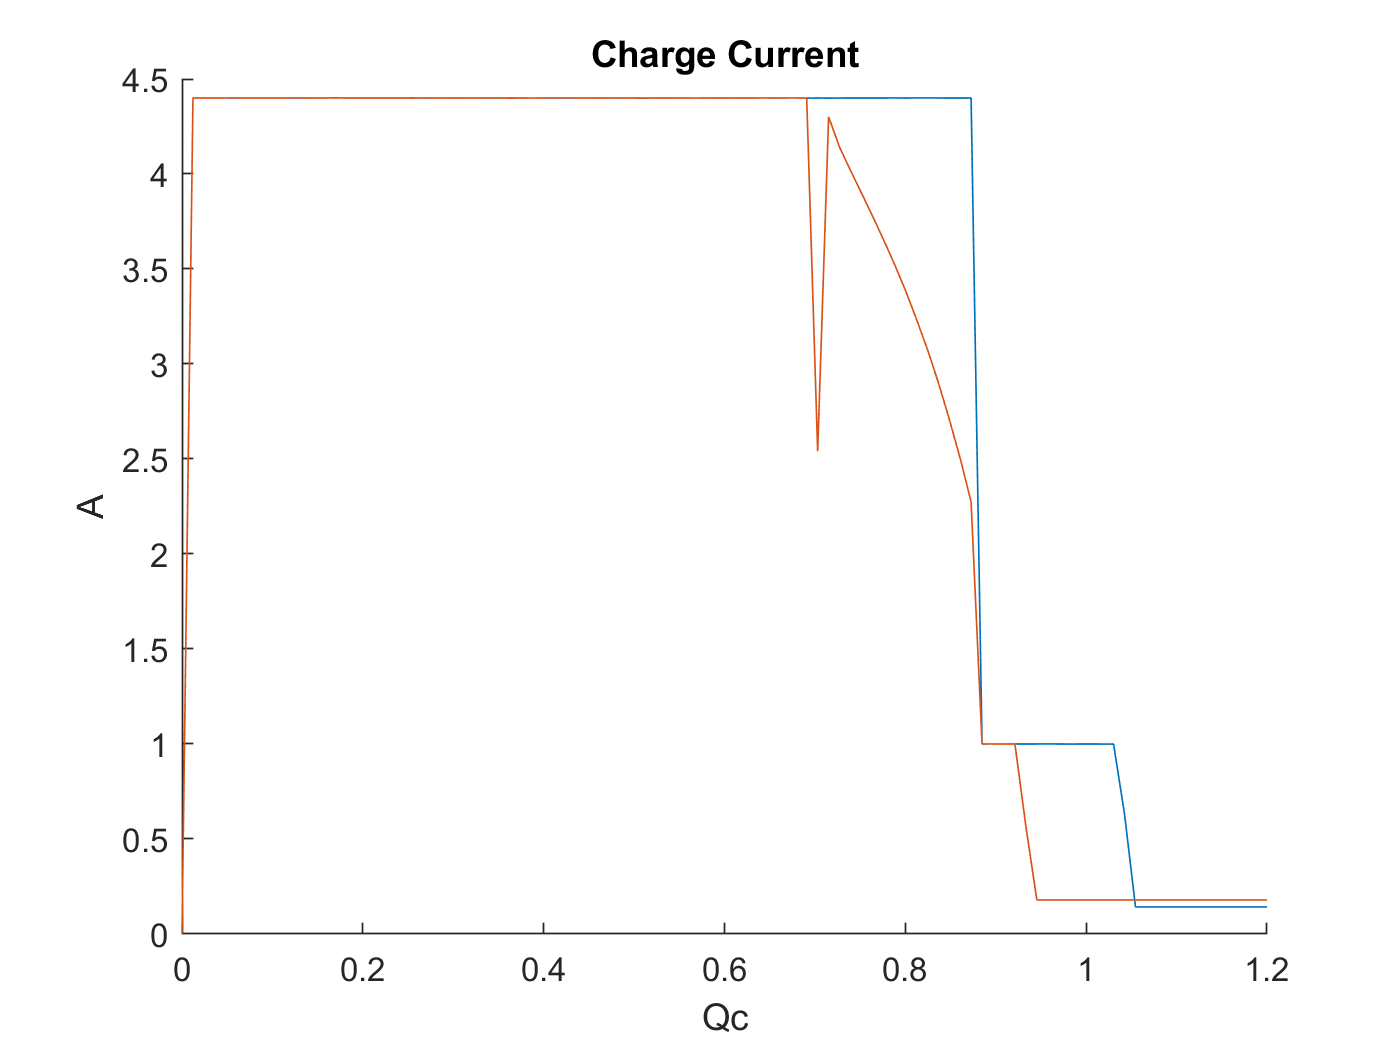


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c, index] = unique(trainData(test_bat).cycles(i).Qc,"first");
    %[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
    y_c = trainData(test_bat).cycles(i).I(index);
    new_x_c = linspace(0,1.2,100);
    new_y_c = interp1(x_c,y_c,new_x_c,'linear');
    new_y_c = fillmissing(new_y_c,'nearest');
    plot(new_x_c,new_y_c);  
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'


length(new_x_c)

ans = 100

index_first = index

index_first =      1
     2
    25
    48
    53
    57
    60
    64
    66
    69


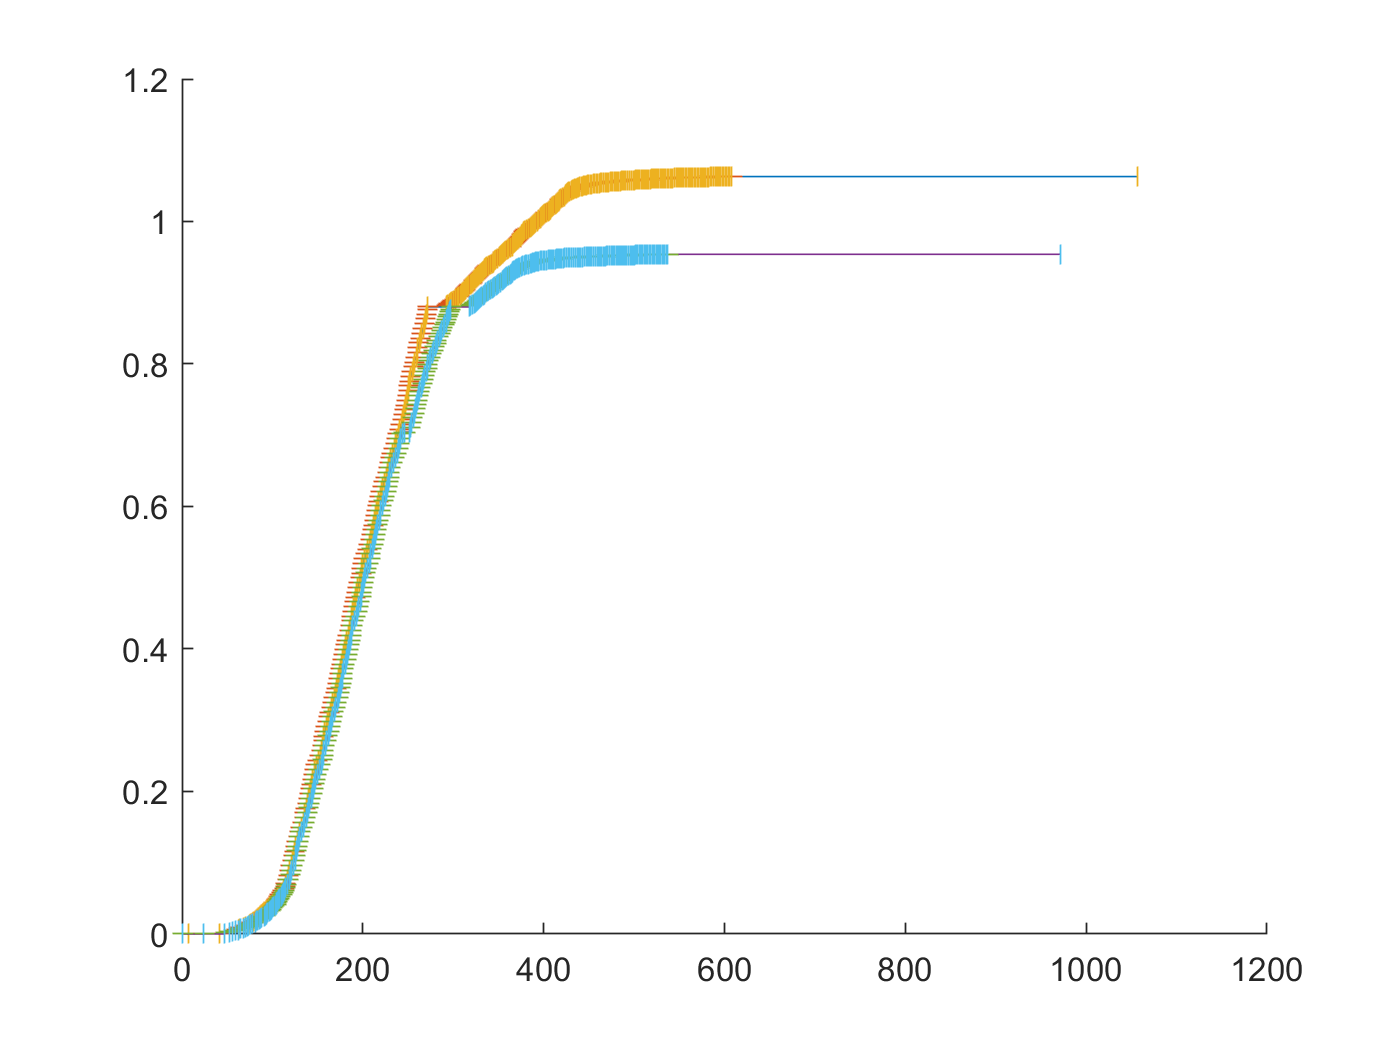

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c_first, index_first] = unique(trainData(test_bat).cycles(i).Qc,"first");
    [x_c_last, index_last] = unique(trainData(test_bat).cycles(i).Qc,"last");
    plot(trainData(test_bat).cycles(i).Qc)
    plot(index_first,x_c_first,'_')
    plot(index_last,x_c_last,'|')
    end
end
hold off

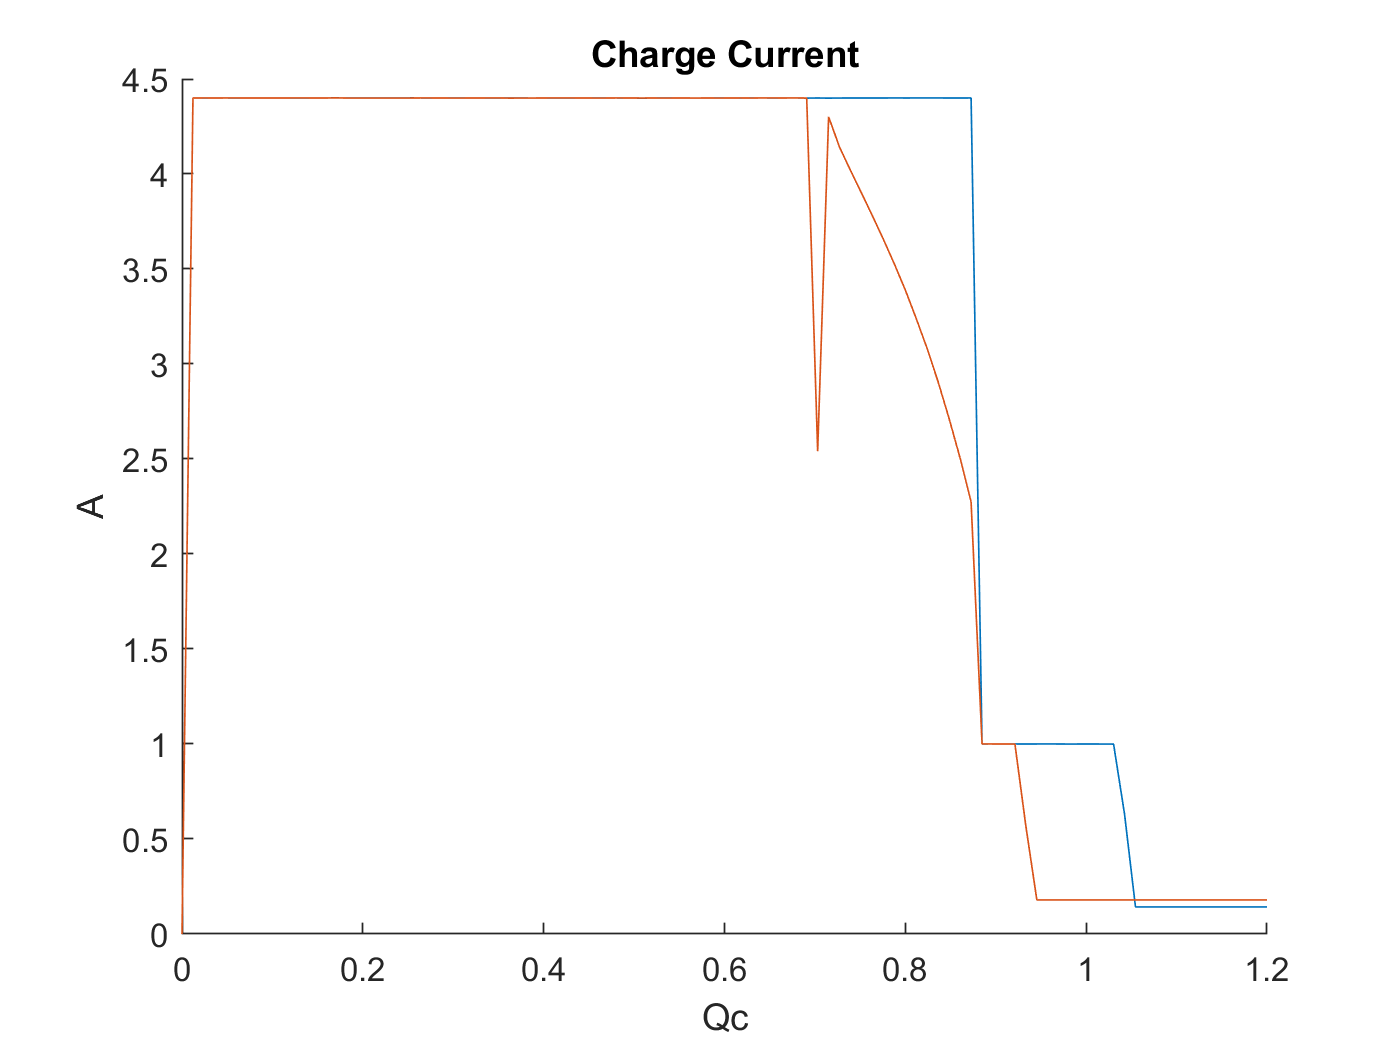


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c, index] = unique(trainData(test_bat).cycles(i).Qc,"last");
    %[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
    y_c = trainData(test_bat).cycles(i).I(index);
    new_x_c = linspace(0,1.2,100);
    new_y_c = interp1(x_c,y_c,new_x_c,'linear');
    new_y_c = fillmissing(new_y_c,'nearest');
    plot(new_x_c,new_y_c);  
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'

length(new_x_c)

ans = 100

index_last = index

index_last =      1
    24
    47
    52
    56
    59
    63
    65
    68
    70



indexs = [index_first index_last]

indexs =      1     1
     2    24
    25    47
    48    52
    53    56
    57    59
    60    63
    64    65
    66    68
    69    70


indexs_gap = index_last - index_first

indexs_gap =      0
    22
    22
     4
     3
     2
     3
     1
     2
     1


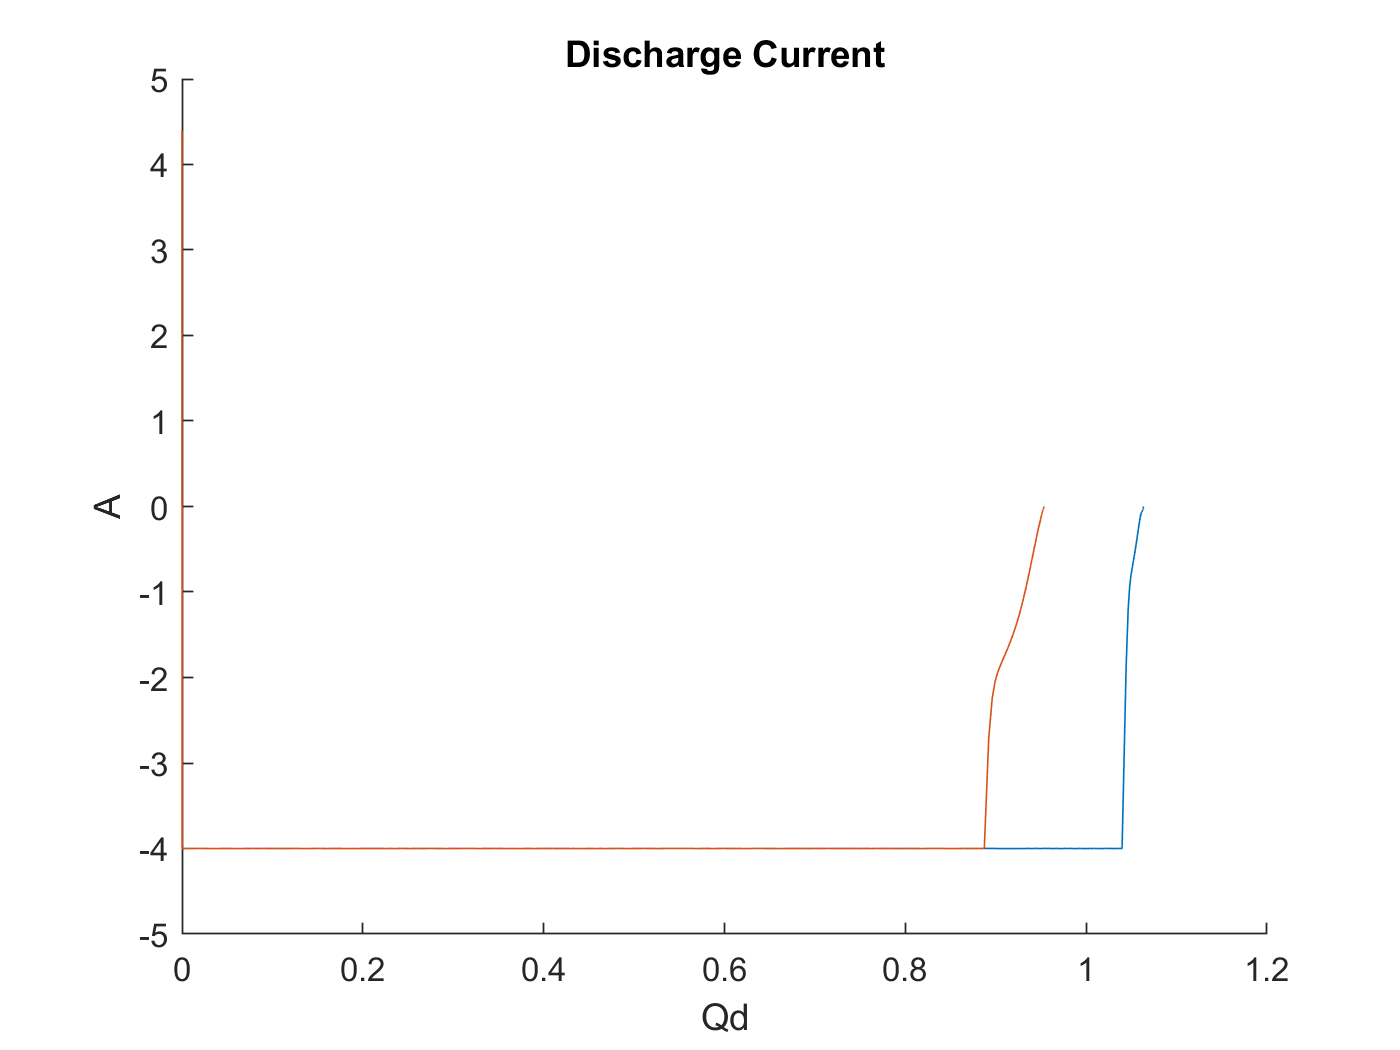


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).I)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Current'

# 테스트 한것들 

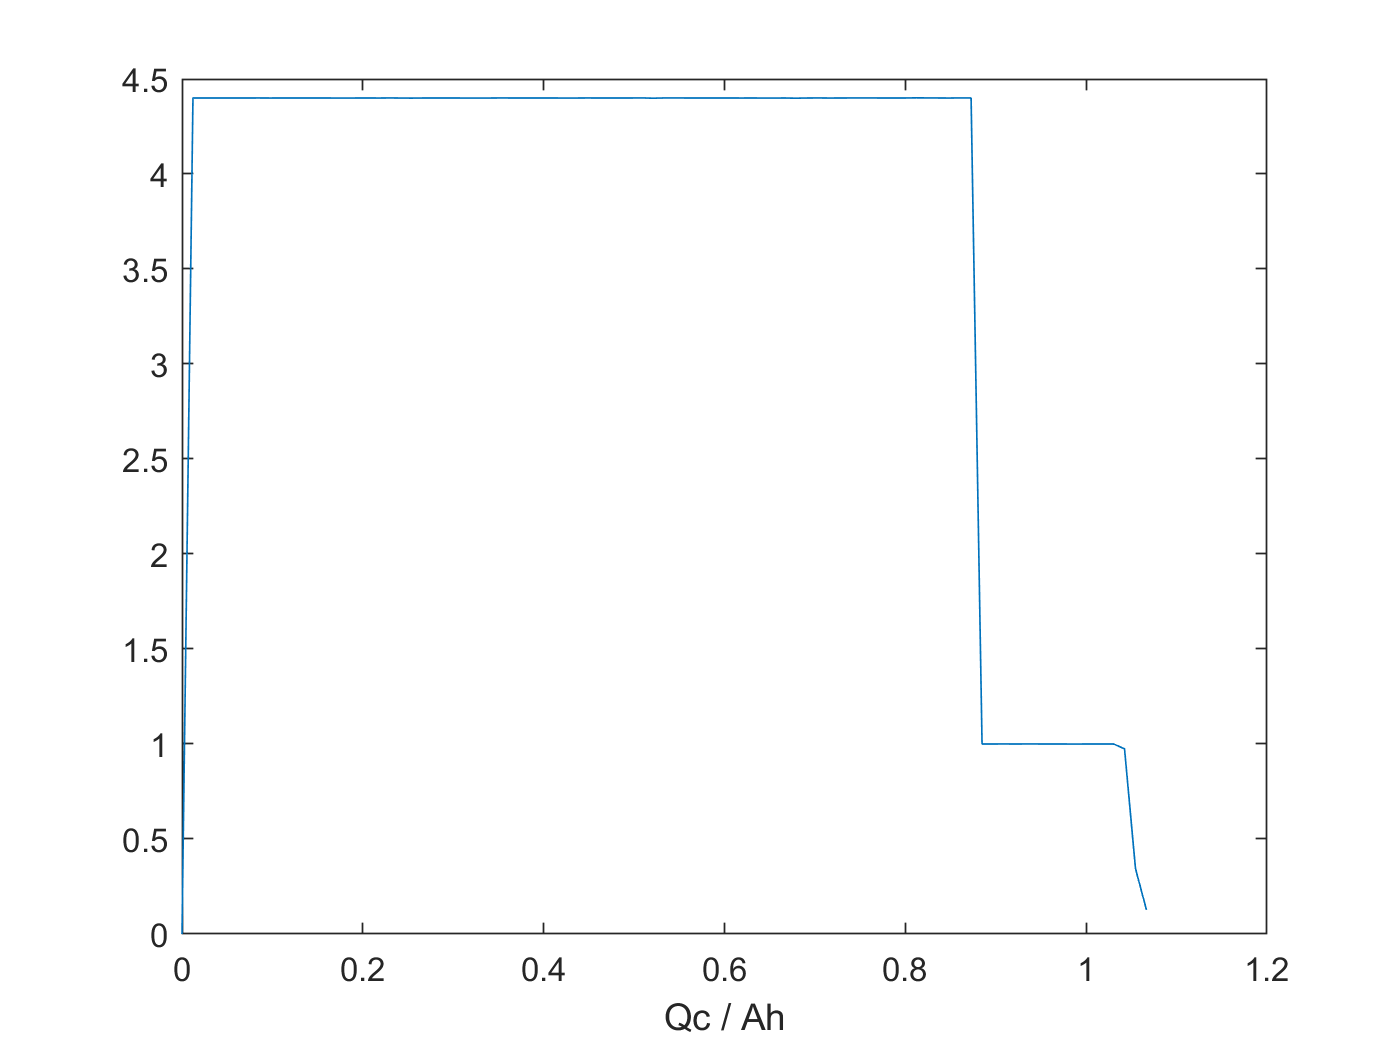


[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).I(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


idxNon = isnan(new_y_c )

idxNon = 1×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =          0    4.4001    4.4000    4.4001    4.4001    4.3999    4.4000    4.4001    4.3998    4.4001    4.4001    4.4001    4.4000    4.4000    4.3998    4.3997    4.3999    4.4000    4.3998    4.4003    4.3997    4.3994    4.3999    4.3999    4.4001    4.4000    4.3997    4.3998    4.3998    4.4002    4.4001    4.4000    4.4000    4.4001    4.3999    4.3998    4.3999    4.4002    4.3999    4.3999    4.4001    4.4000    4.4004    4.3990    4.4002    4.4002    4.4001    4.4000    4.3999    4.3999


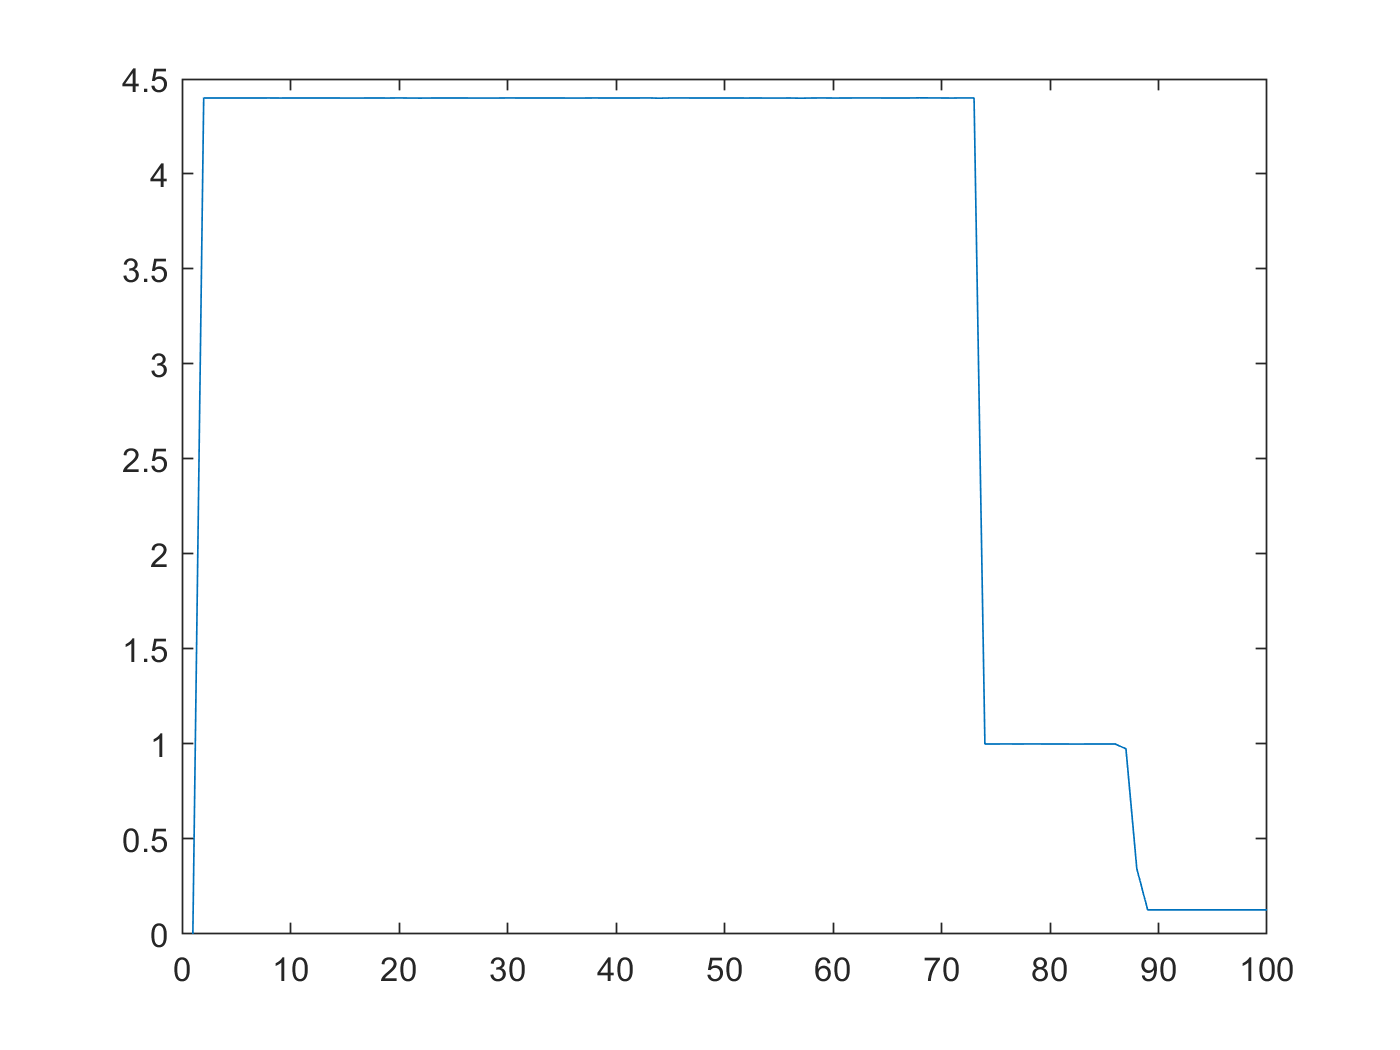

plot(new_y_c_fix)

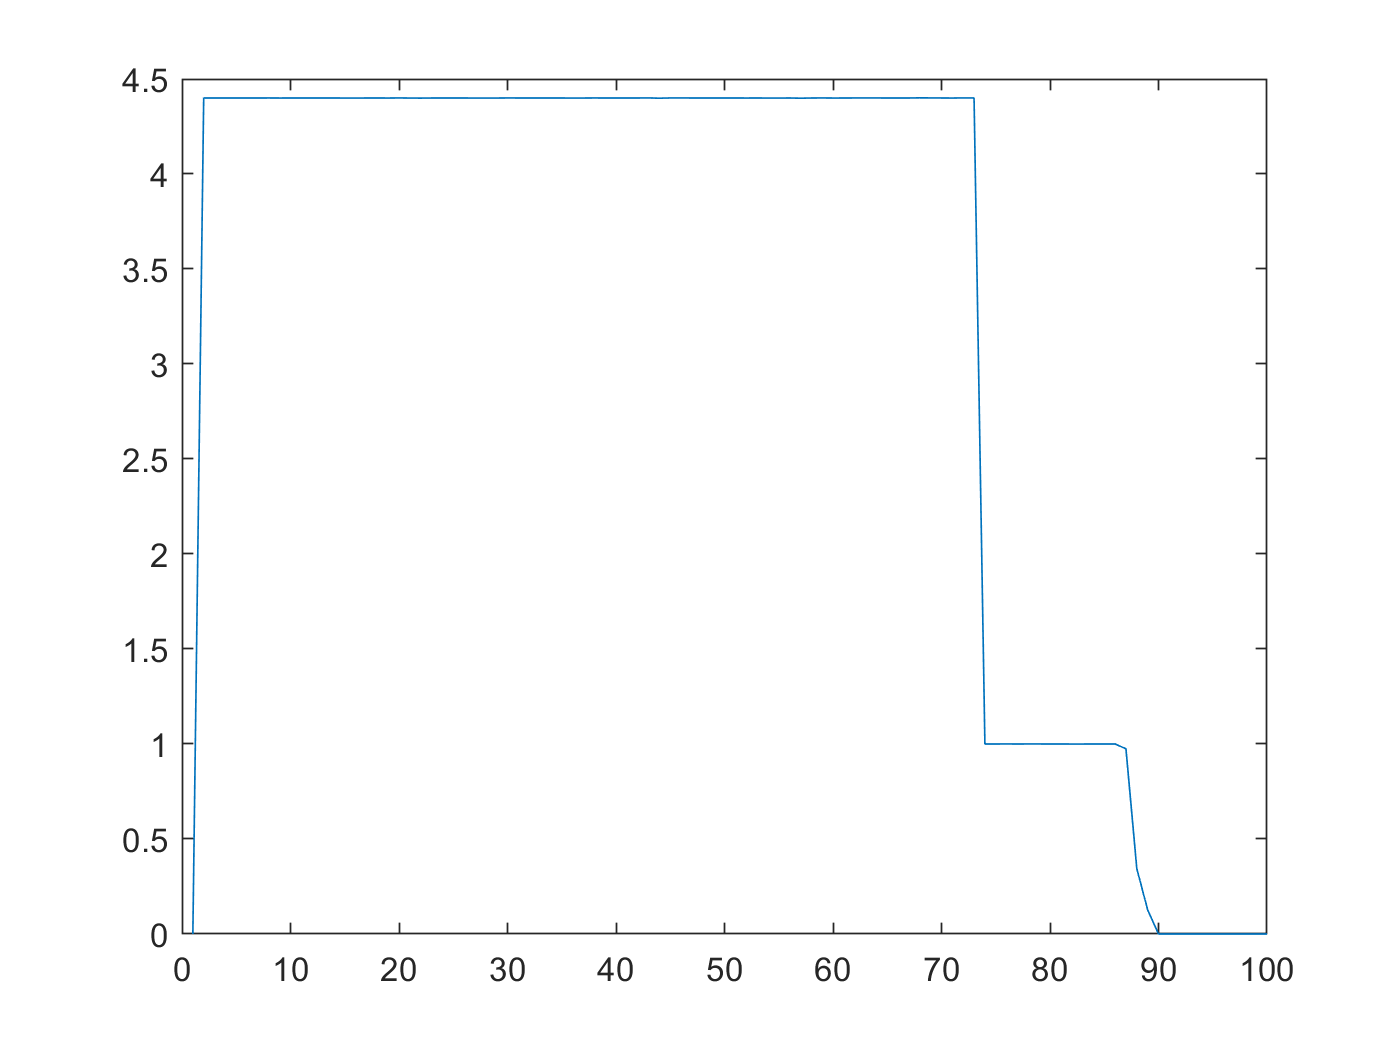

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

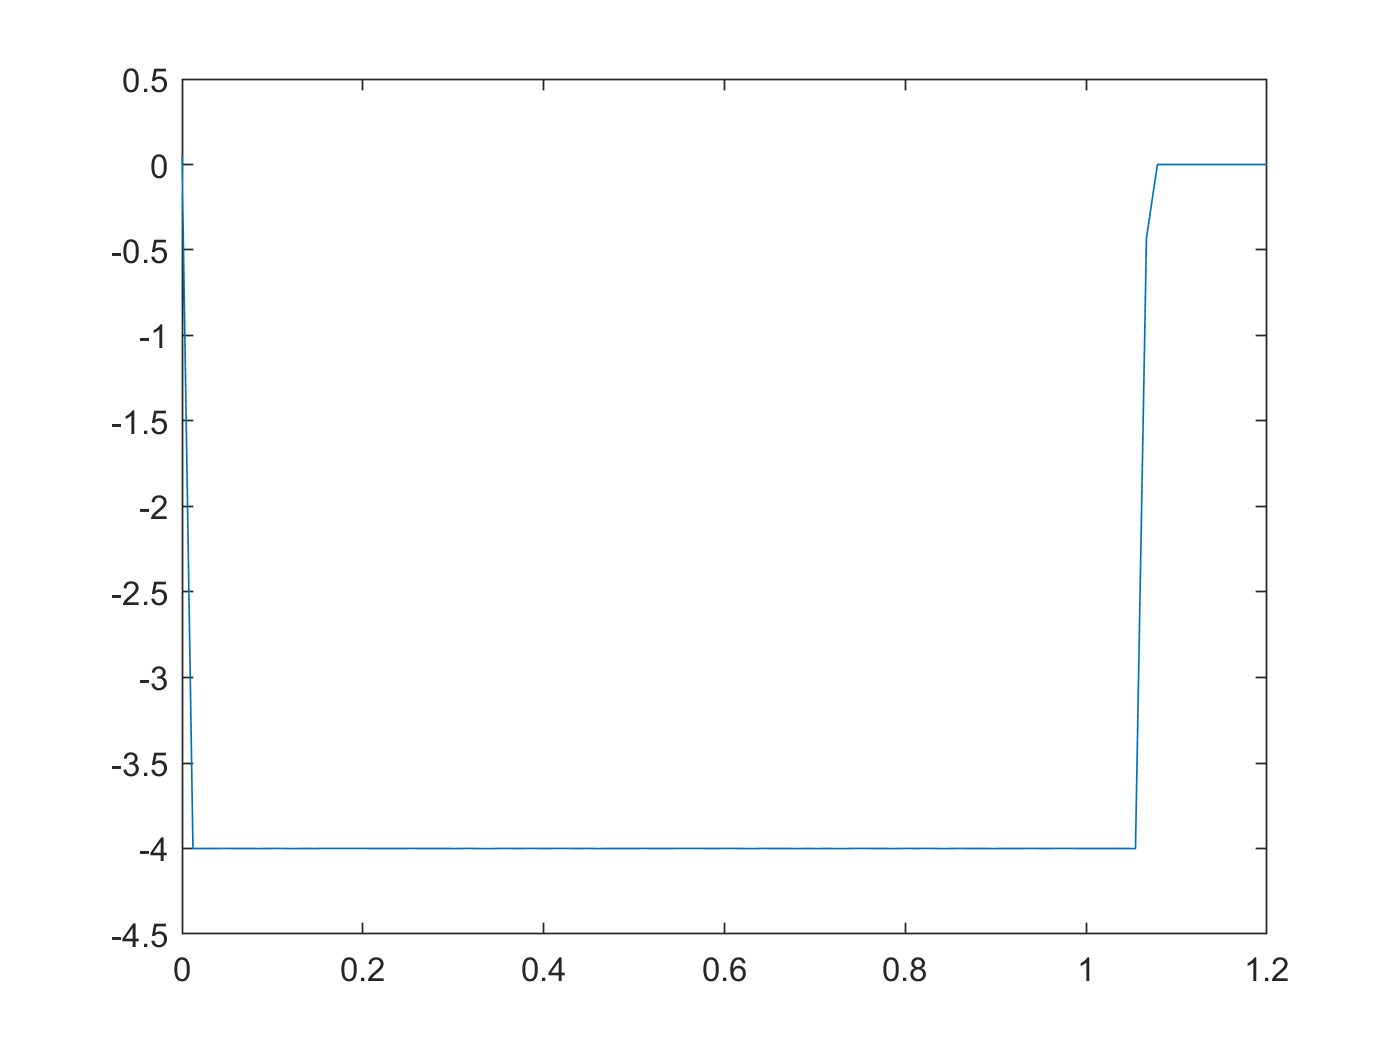

%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).I(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

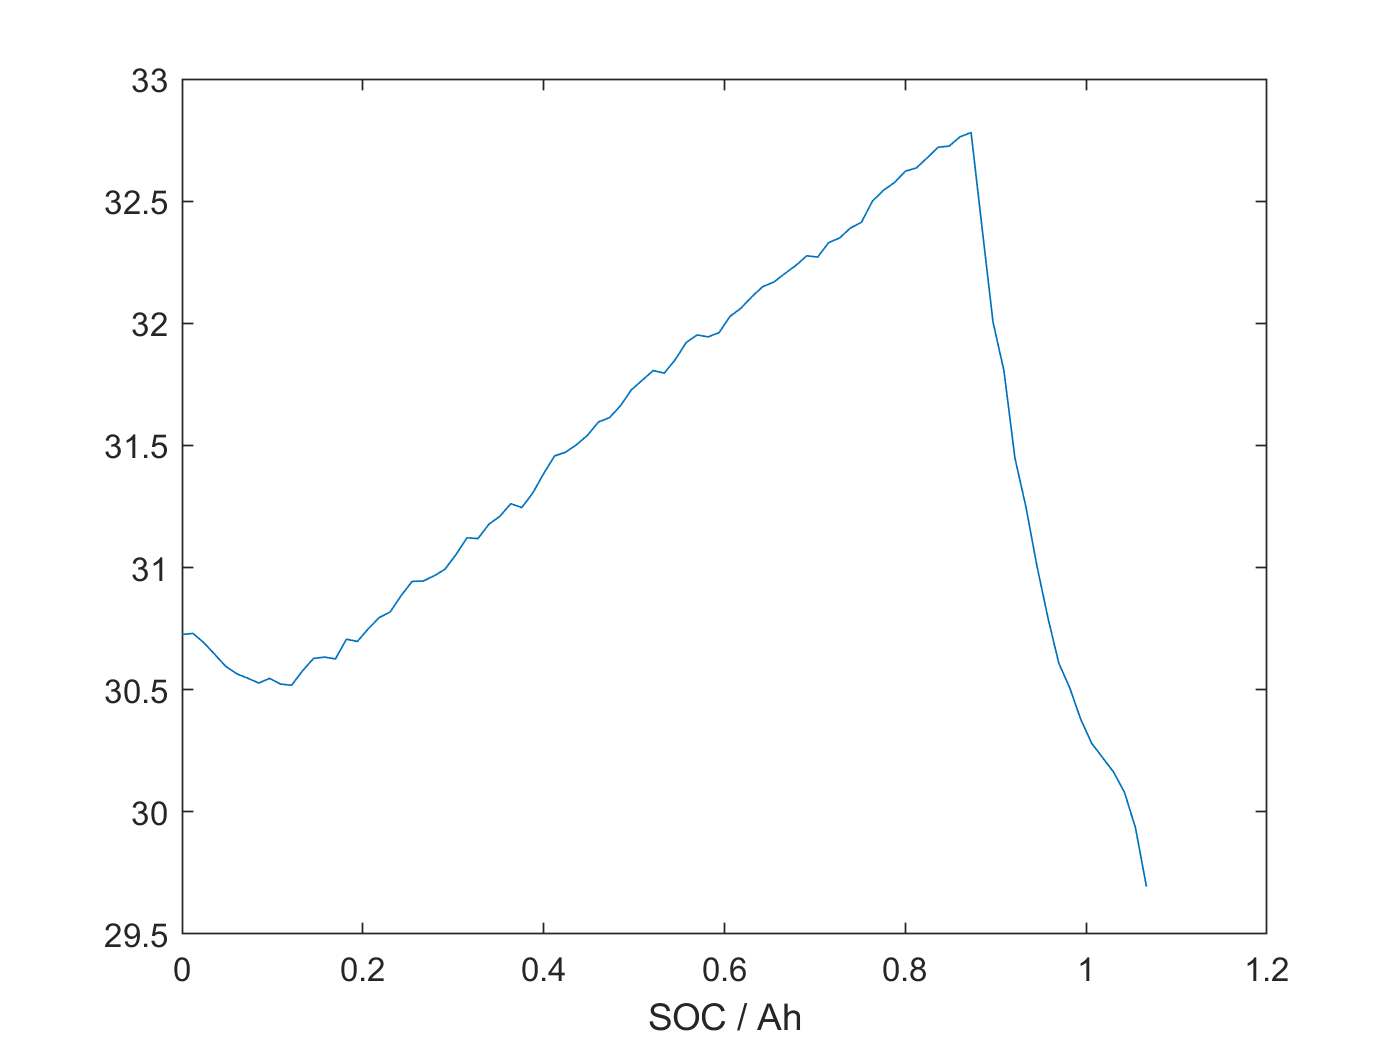

[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).T(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =    30.7258   30.7306   30.6922   30.6439   30.5951   30.5652   30.5472   30.5274   30.5463   30.5230   30.5182   30.5774   30.6280   30.6334   30.6259   30.7066   30.6976   30.7497   30.7953   30.8187   30.8856   30.9434   30.9449   30.9660   30.9935   31.0532   31.1220   31.1186   31.1772   31.2099   31.2614   31.2456   31.3049   31.3848   31.4571   31.4723   31.5030   31.5415   31.5961   31.6135   31.6619   31.7274   31.7671   31.8066   31.7959   31.8510   31.9211   31.9523   31.9445   31.9616


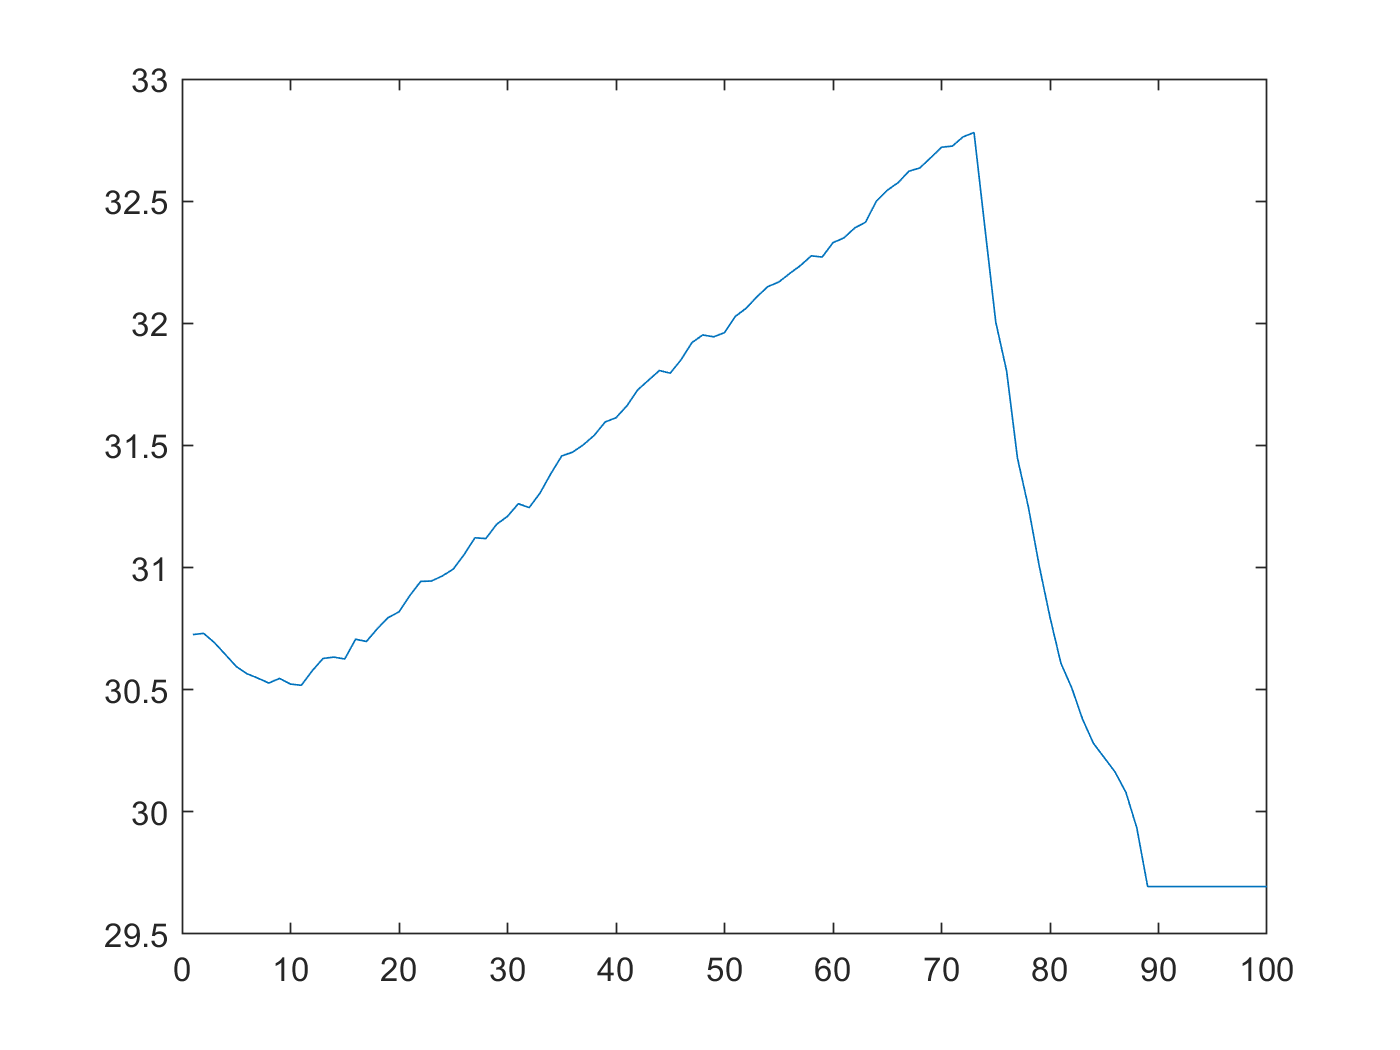

plot(new_y_c_fix)

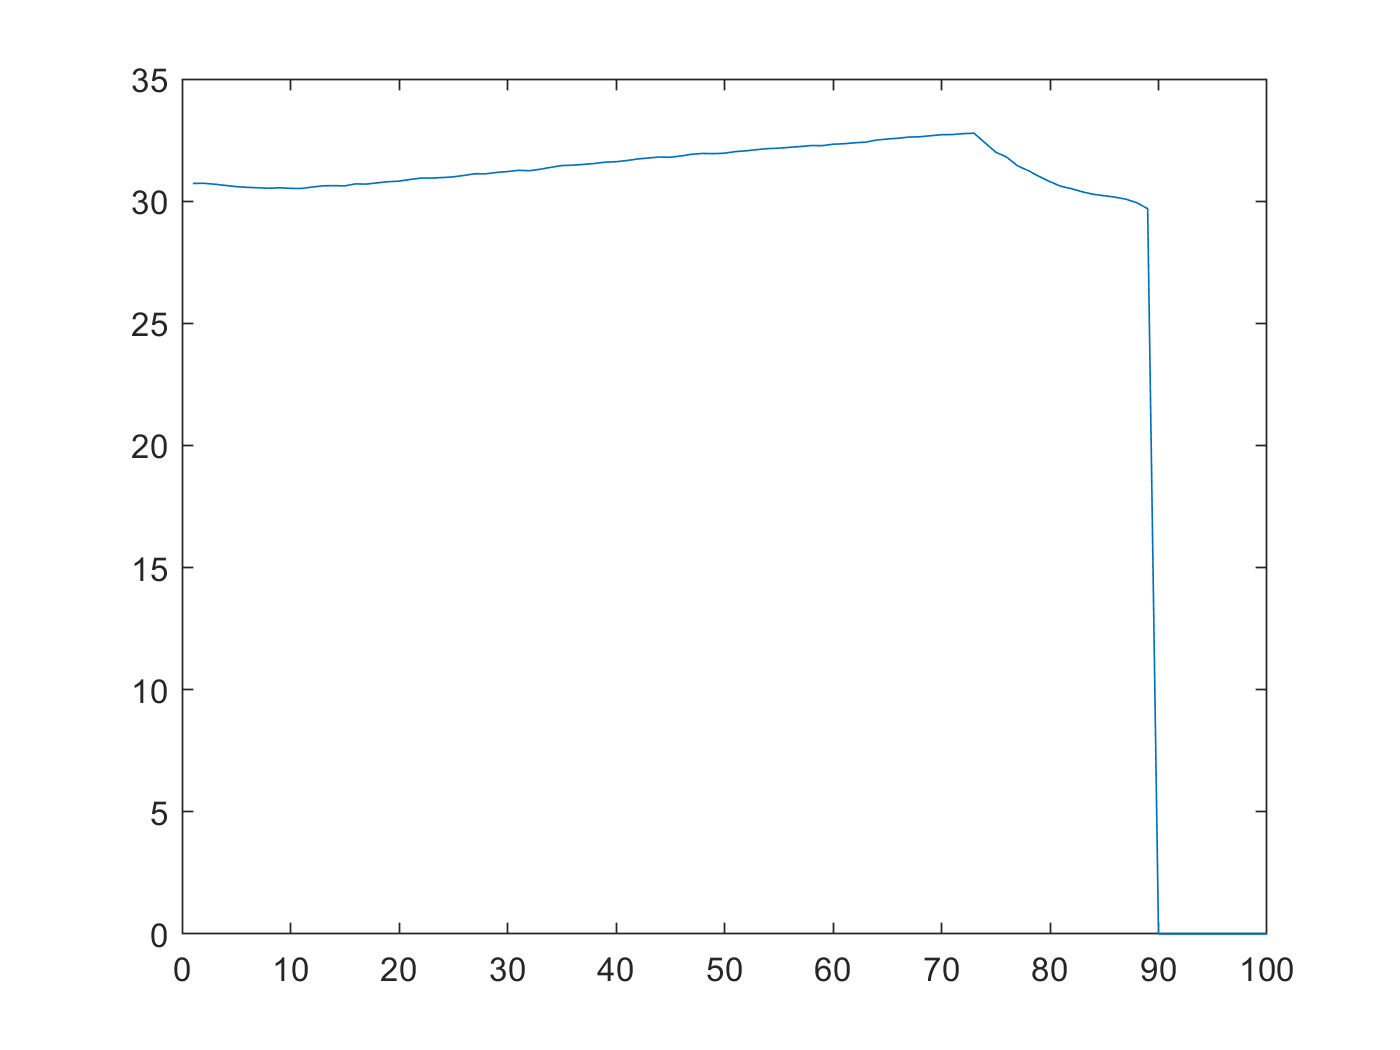

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

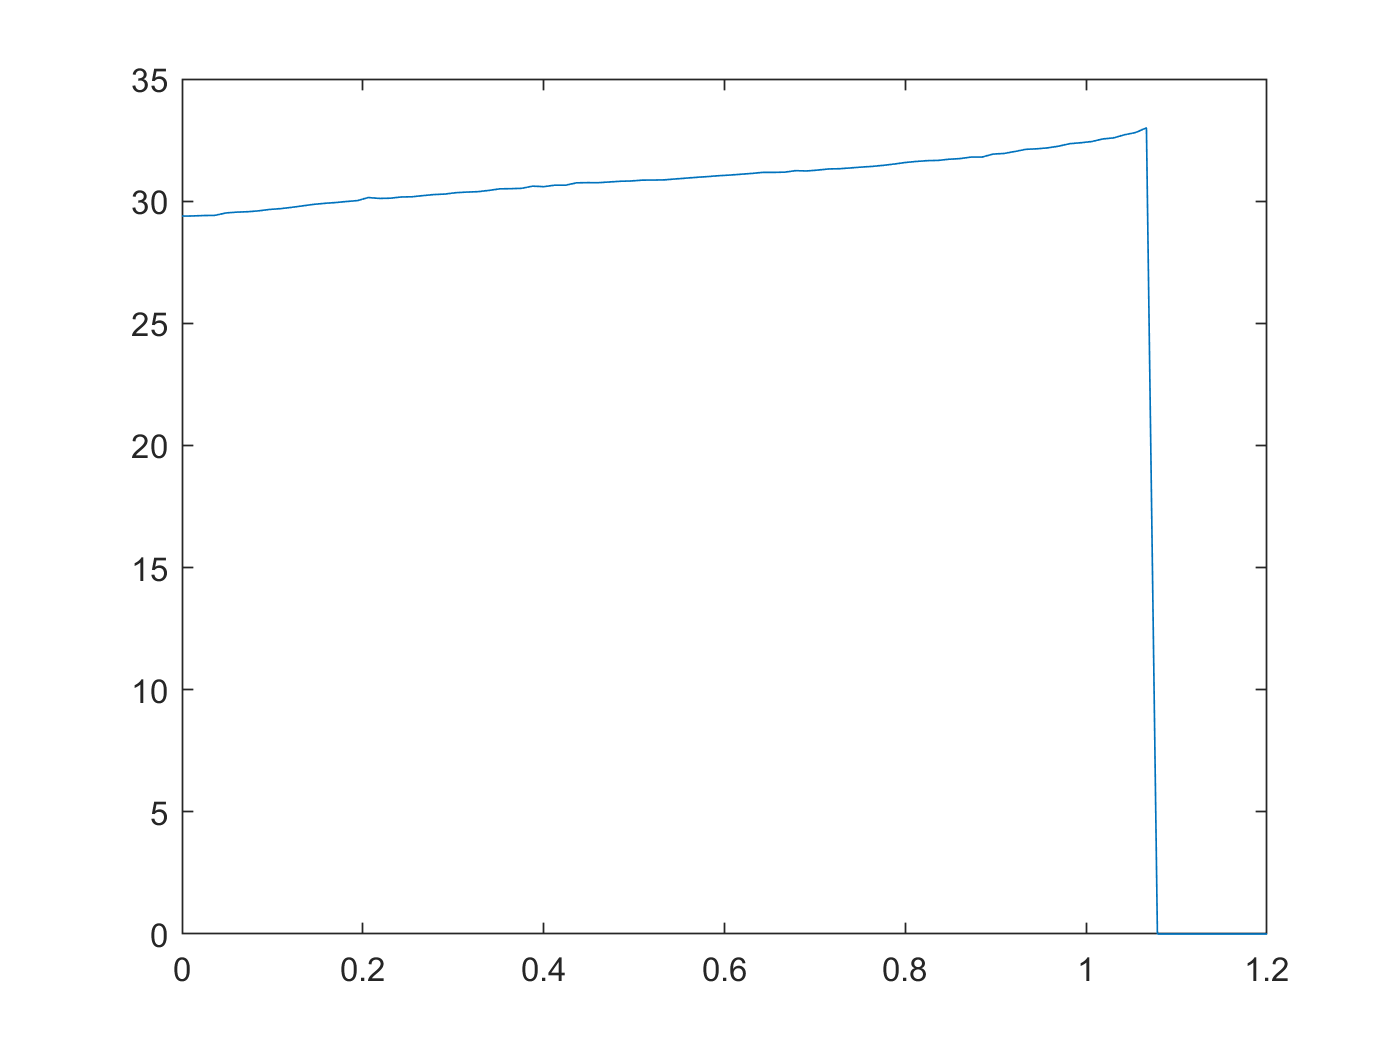

%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).T(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

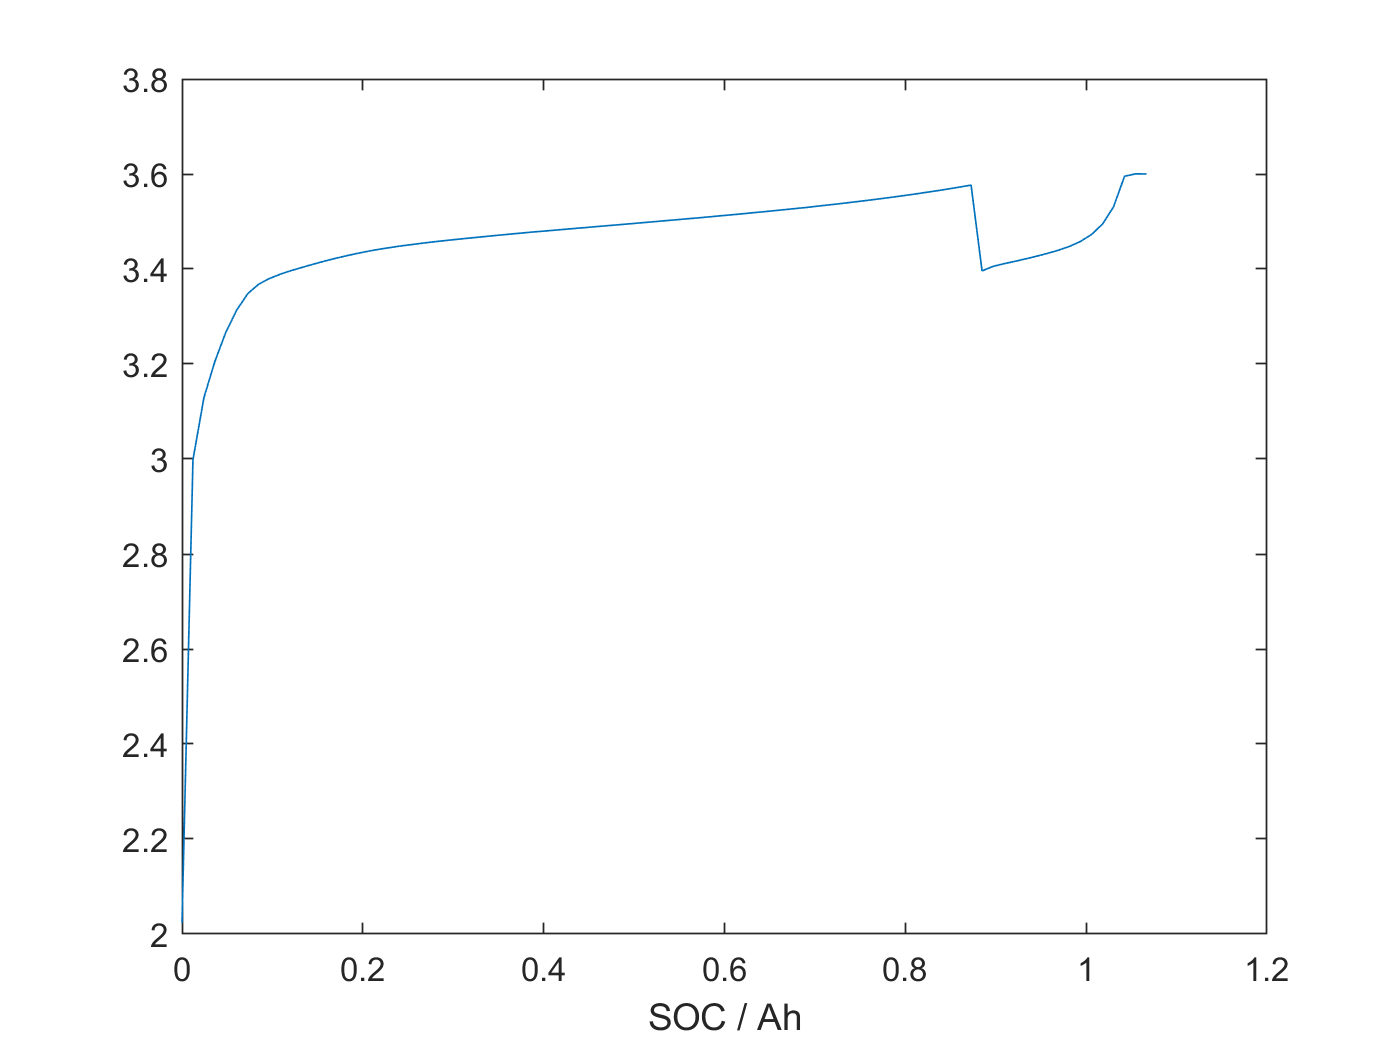

[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).V(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
% https://kr.mathworks.com/matlabcentral/answers/29481-last-non-nan-observation
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =     2.0230    2.9983    3.1292    3.2055    3.2669    3.3139    3.3482    3.3681    3.3802    3.3894    3.3969    3.4037    3.4103    3.4165    3.4224    3.4278    3.4329    3.4375    3.4416    3.4452    3.4486    3.4516    3.4545    3.4573    3.4598    3.4622    3.4646    3.4668    3.4692    3.4714    3.4736    3.4757    3.4779    3.4797    3.4817    3.4837    3.4857    3.4876    3.4897    3.4915    3.4935    3.4954    3.4975    3.4994    3.5015    3.5034    3.5055    3.5074    3.5096    3.5117


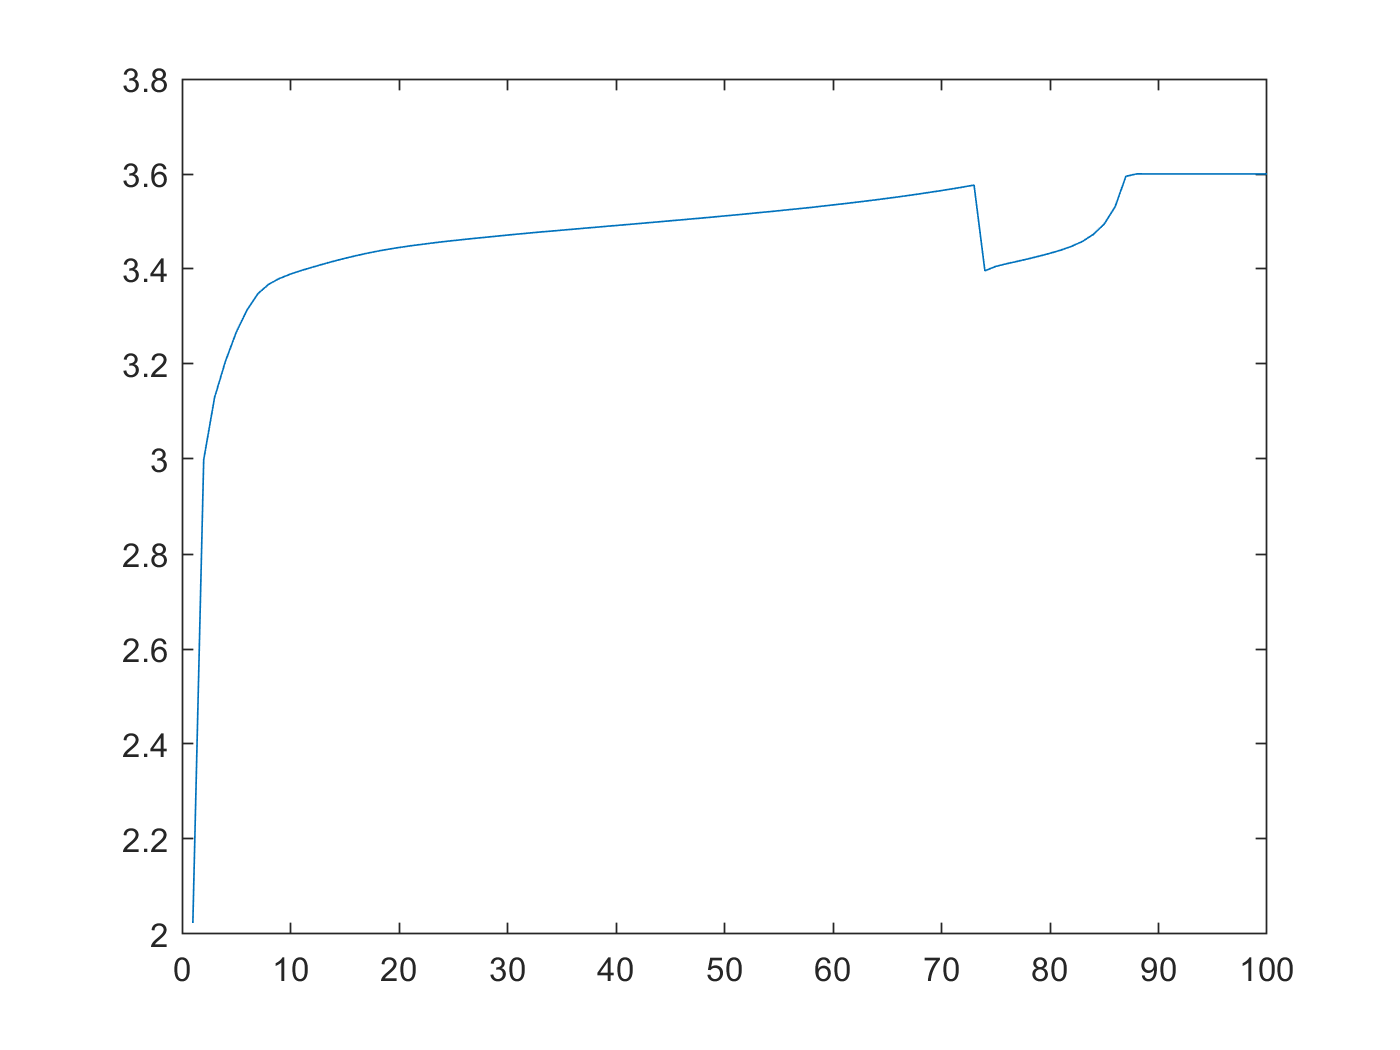

plot(new_y_c_fix)

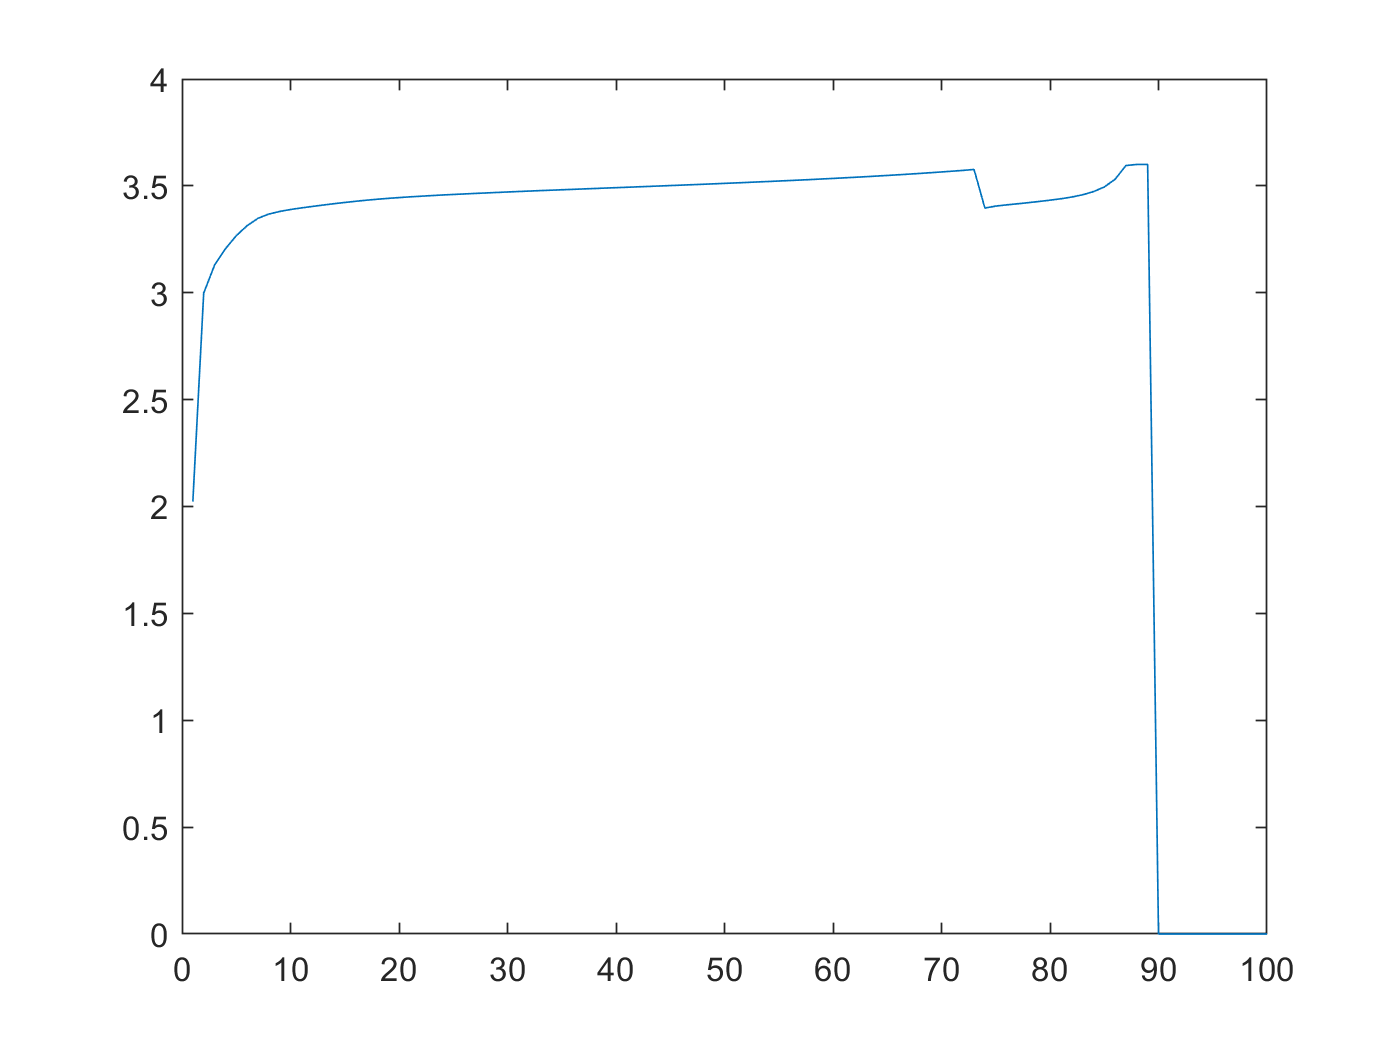


% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

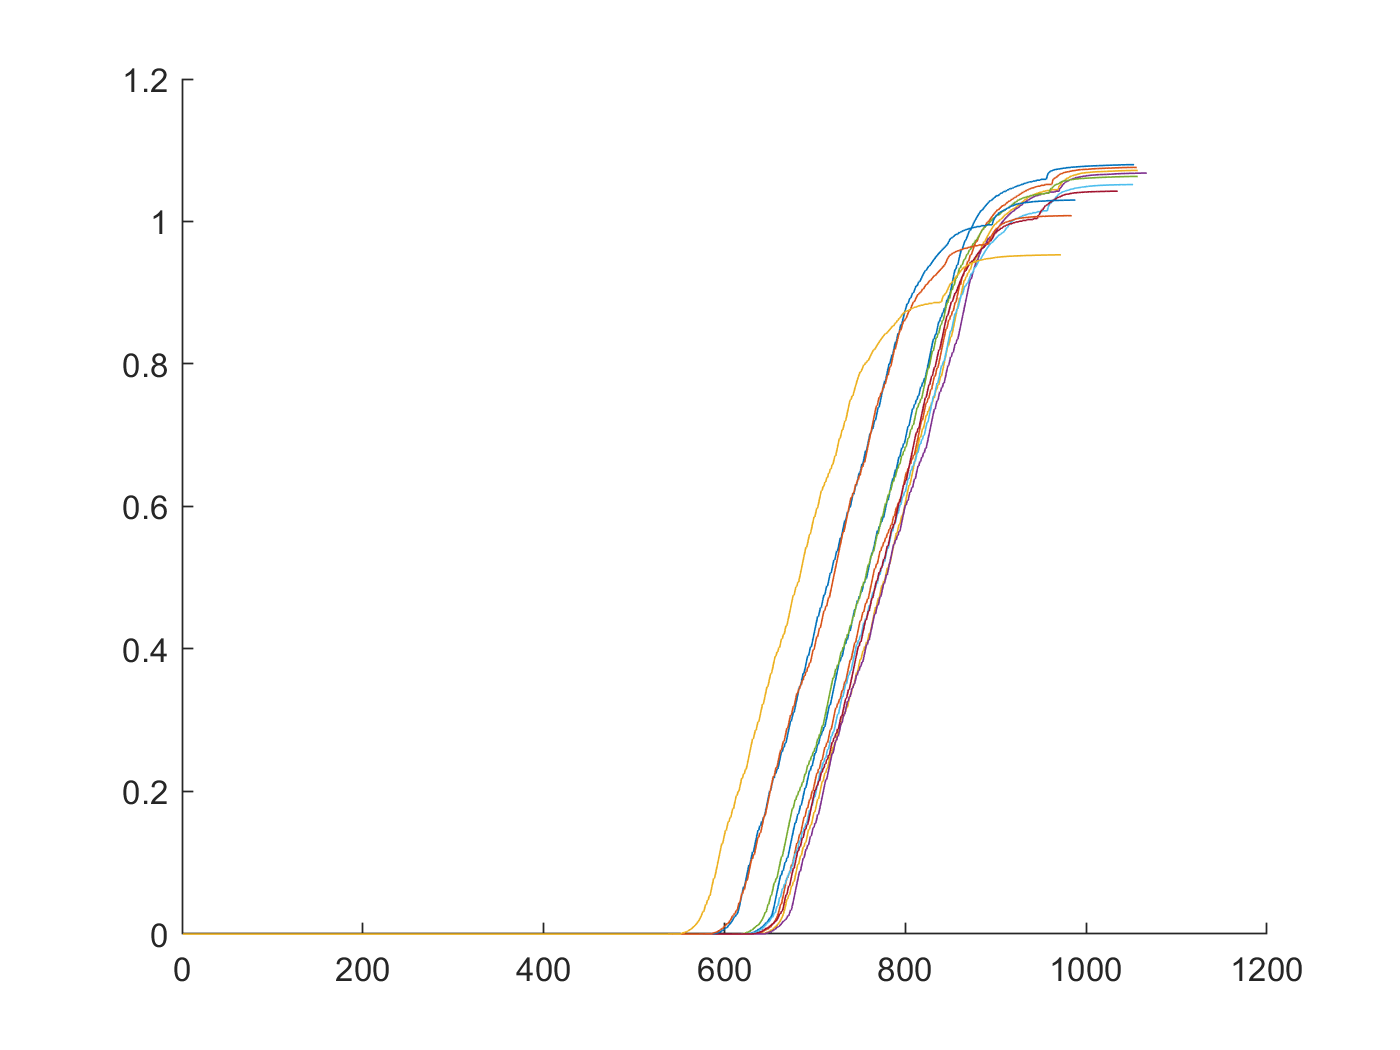

figure
hold on
for i=1:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
        plot(trainData(test_bat).cycles(i).Qd)
    end
end 
hold off 

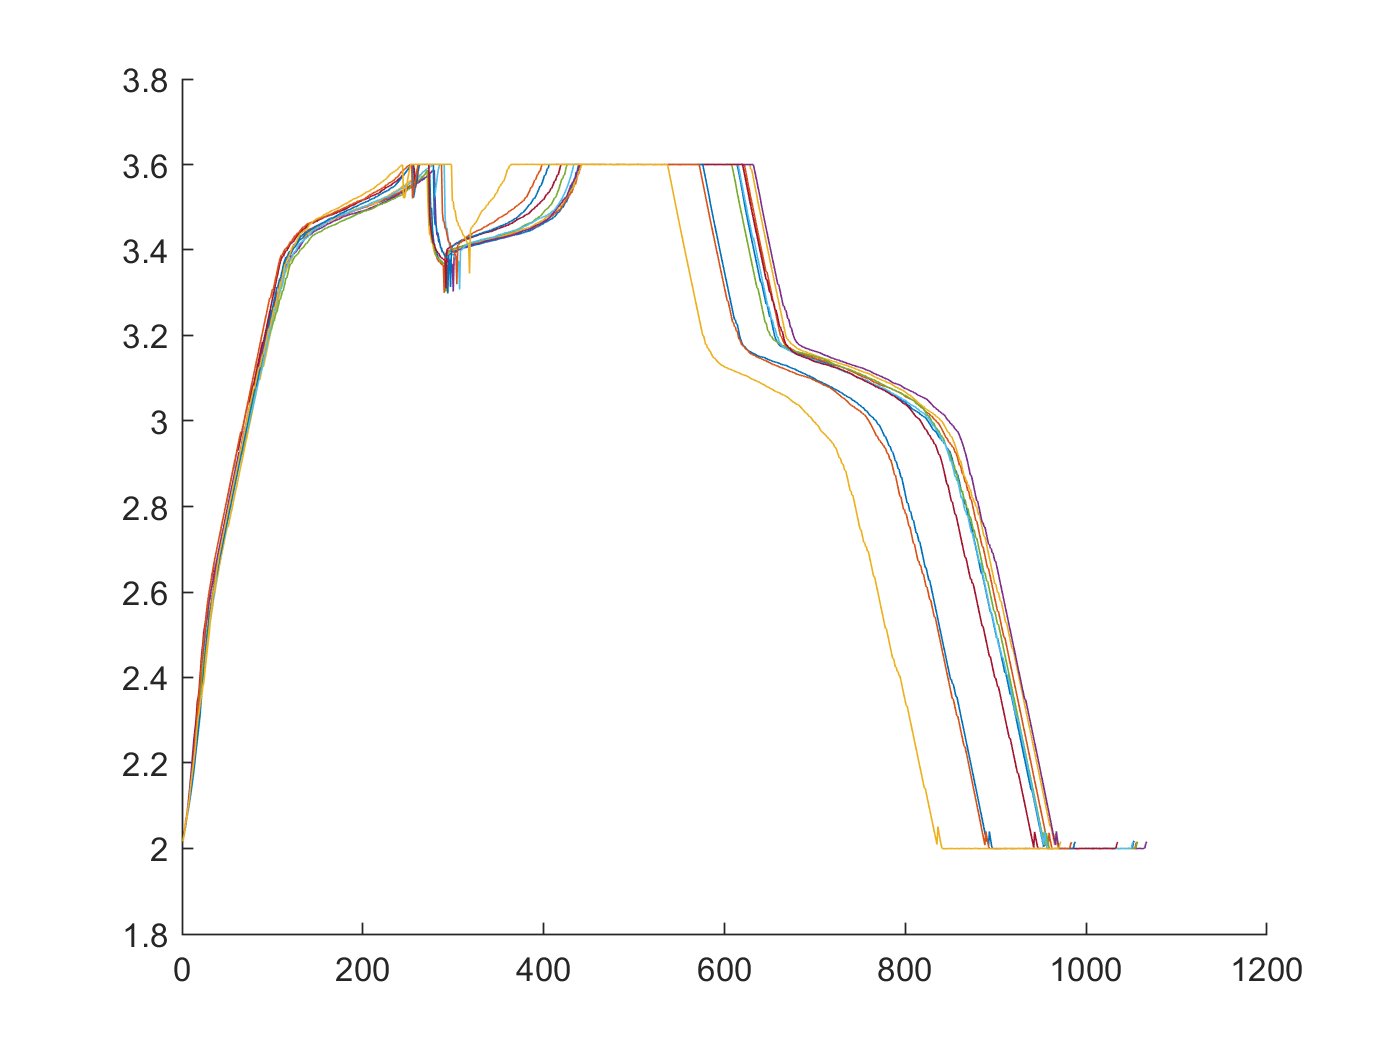

figure
hold on
for i=1:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    plot(trainData(test_bat).cycles(i).V')
    end
end 
hold off 

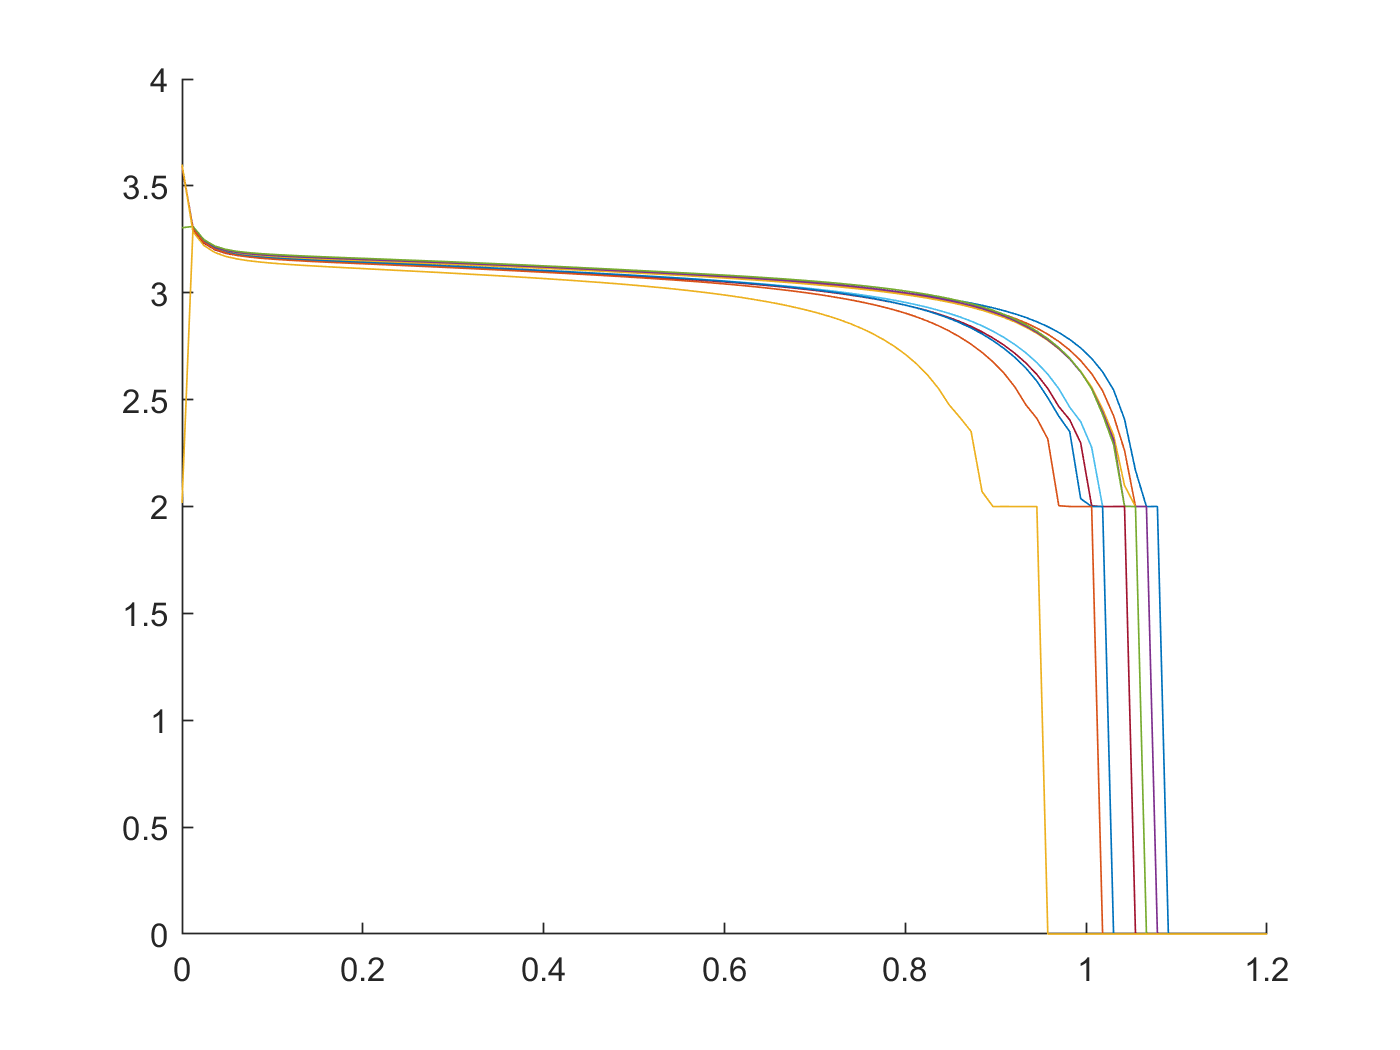

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [x_d, index] = unique(trainData(test_bat).cycles(i).Qd,"last");
    
    y_d = trainData(test_bat).cycles(i).V(index);
    new_x_d = linspace(0,1.2,100);
    new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
    new_y_d(isnan(new_y_d)) = 0;
    plot(new_x_d,new_y_d);
    end
end 
hold off

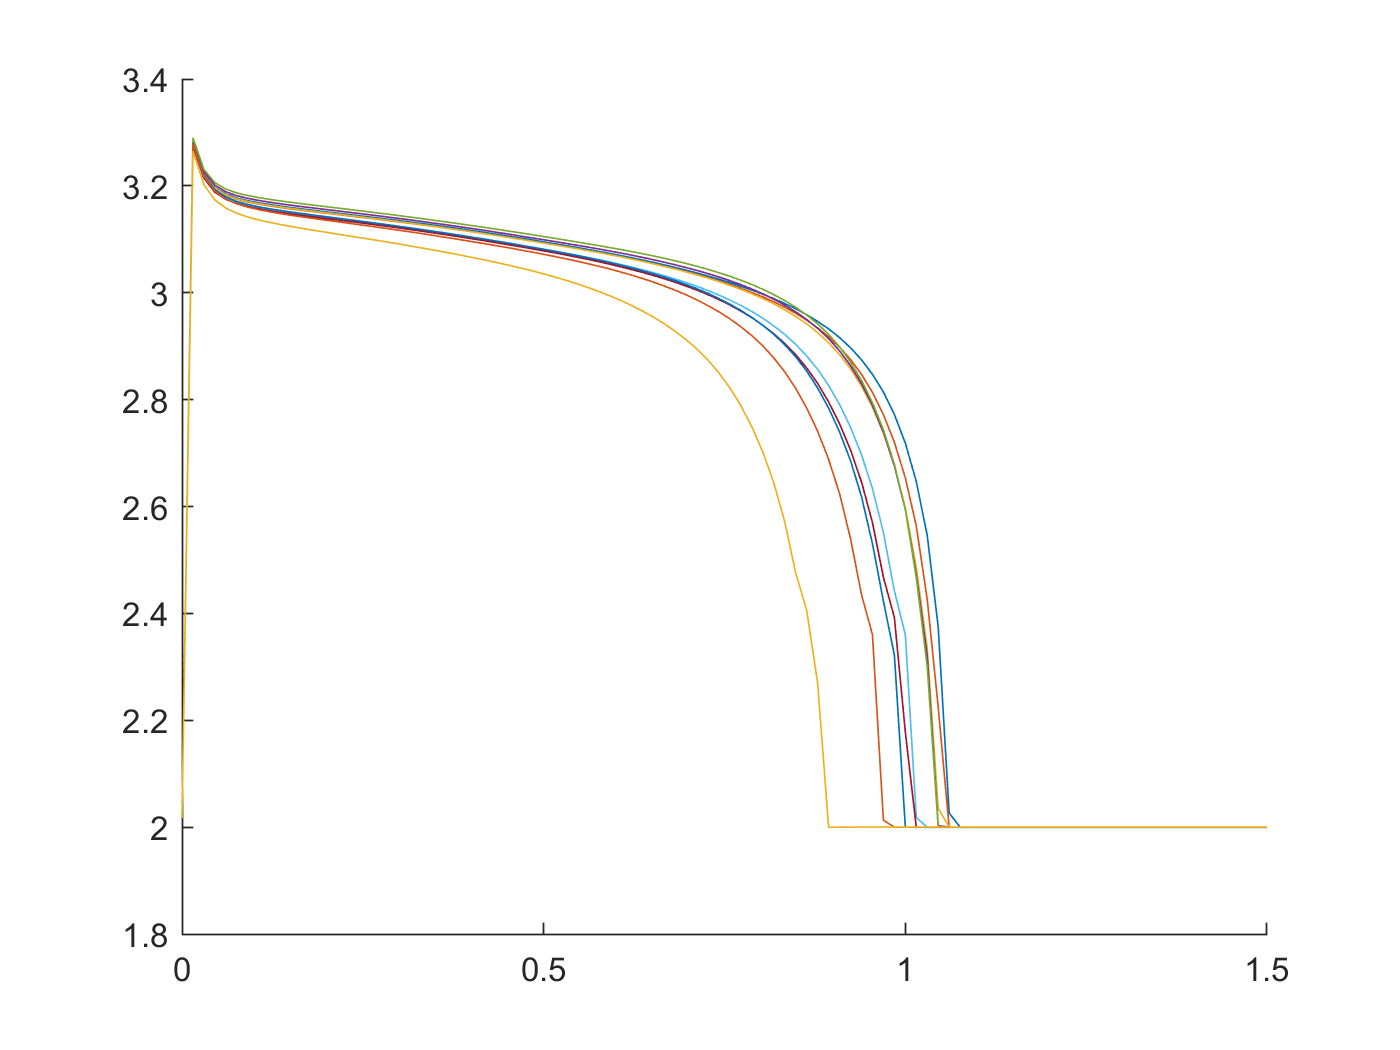

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    Qd_tmp = trainData(test_bat).cycles(i).Qd;
    Qd_tmp(Qd_tmp<0) = 0;
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [xq, index] = unique(Qd_tmp,"first");
    
    yV = trainData(test_bat).cycles(i).V(index);
    xq_new = linspace(0,1.5,100);
    yV = interp1(xq,yV,xq_new,'linear'); 
    yV = fillmissing(yV,'nearest');
    %new_y_d(isnan(new_y_d)) = 0;
    plot(xq_new,yV);
    end
end 
hold off

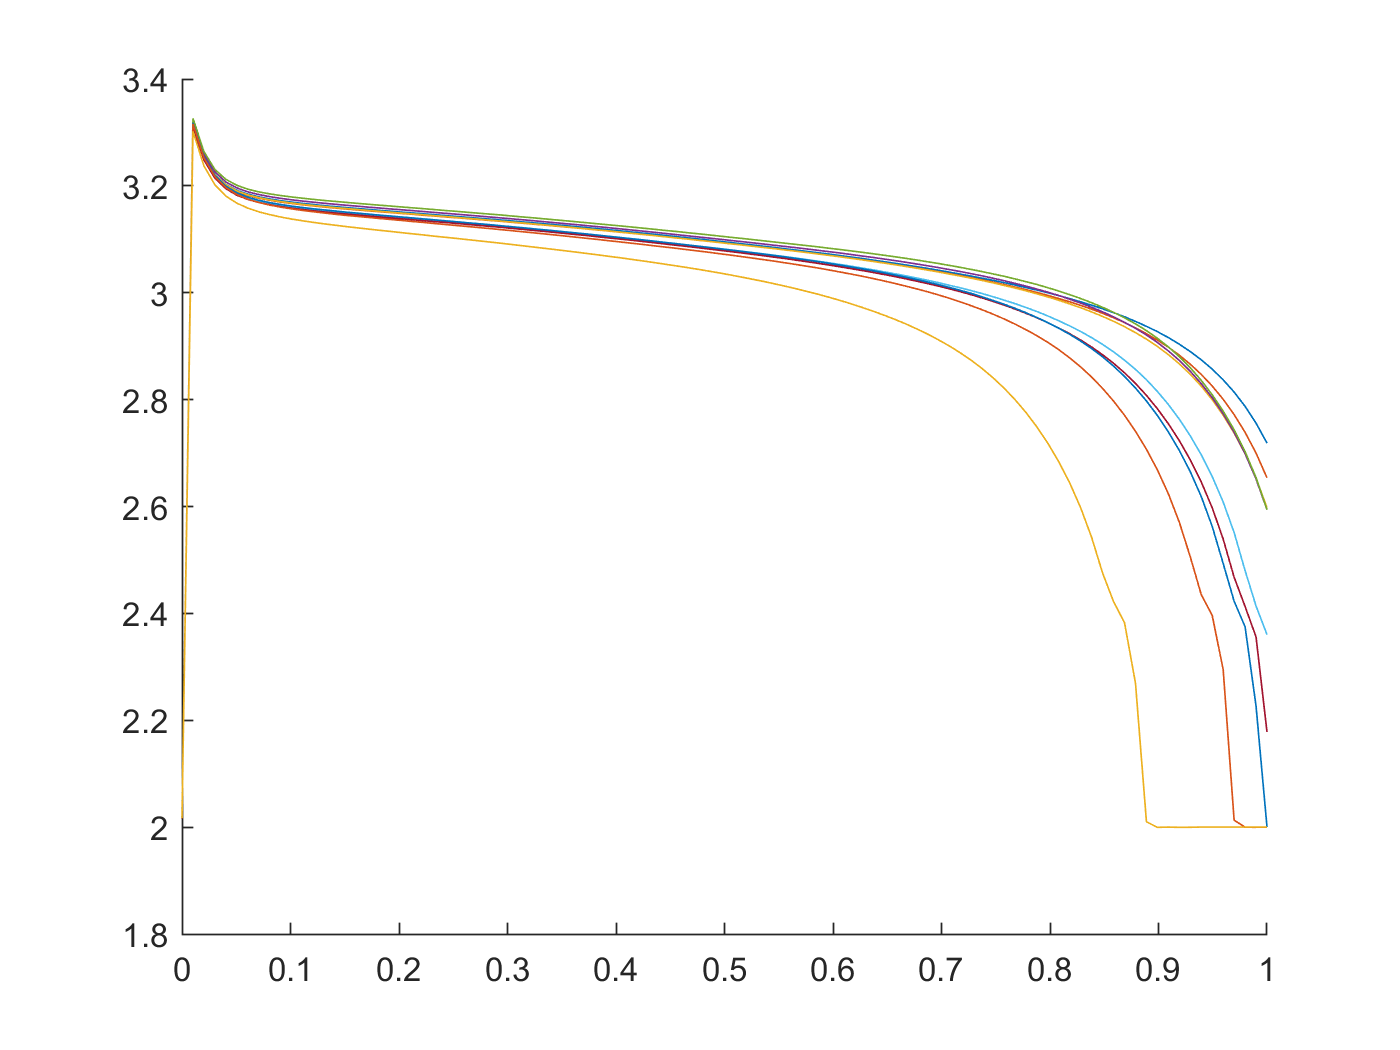

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    Qd_tmp = trainData(test_bat).cycles(i).Qd;
    Qd_tmp(Qd_tmp<0) = 0;
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [xq, index] = unique(Qd_tmp,"first");
    
    yV = trainData(test_bat).cycles(i).V(index);
    xq_new = linspace(0,1.0,100);
    yV = interp1(xq,yV,xq_new,'linear'); 
    yV = fillmissing(yV,'nearest');
    %new_y_d(isnan(new_y_d)) = 0;
    plot(xq_new,yV);
    end
end 
hold off

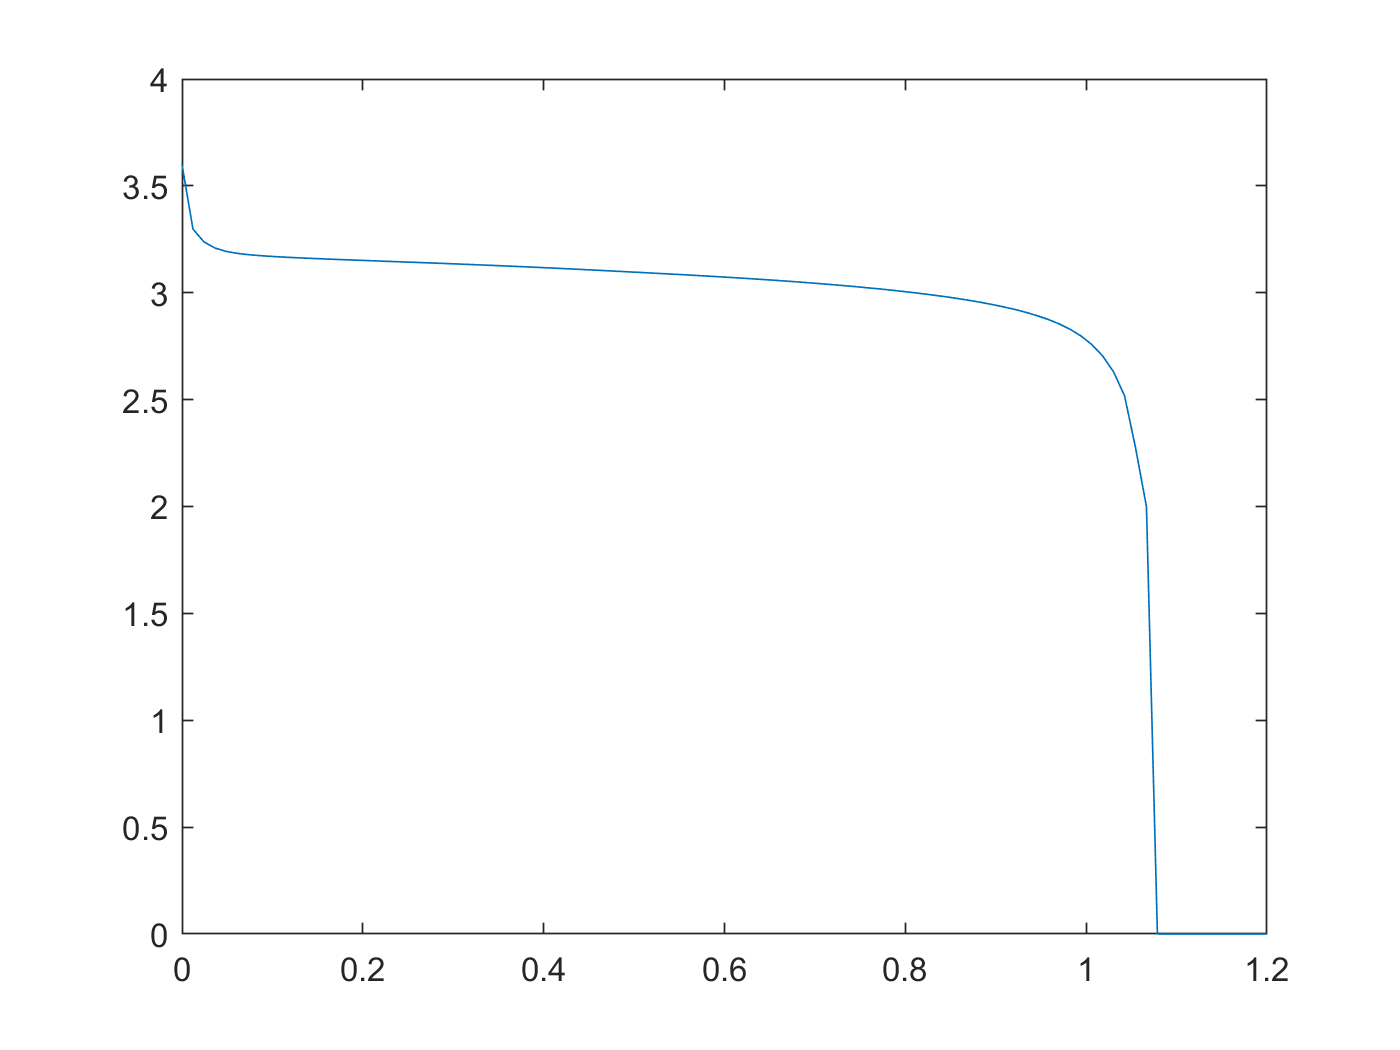


%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).V(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

%{
x_indexs = find(trainData(test_bat).cycles(2).Qd')
x_index = x_indexs(1)
x = trainData(test_bat).cycles(2).Qd';
x = x(x_index : end)
y = trainData(test_bat).cycles(2).V';
y = y(x_index : end)
new_x = linspace(0,1.2,100);
new_y = interp1(x,y,new_x,'linear'); 
plot(new_y)
%}   

# 다시 실험 시작 - 전류는 했으니 전압과 온도에 대해서 하자.

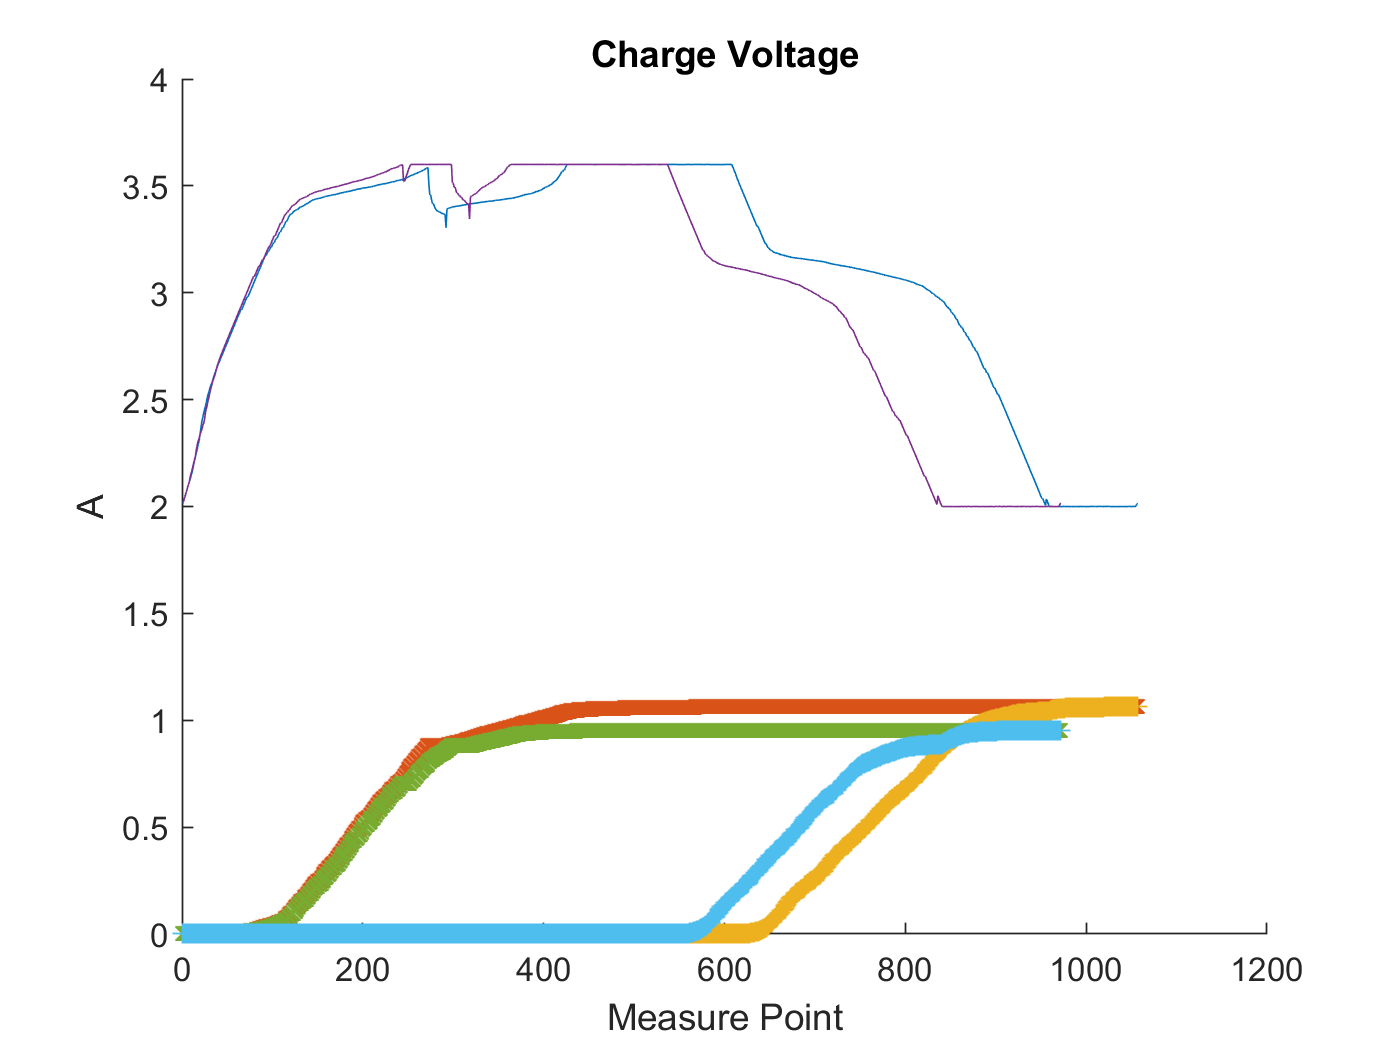

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).V)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Voltage'

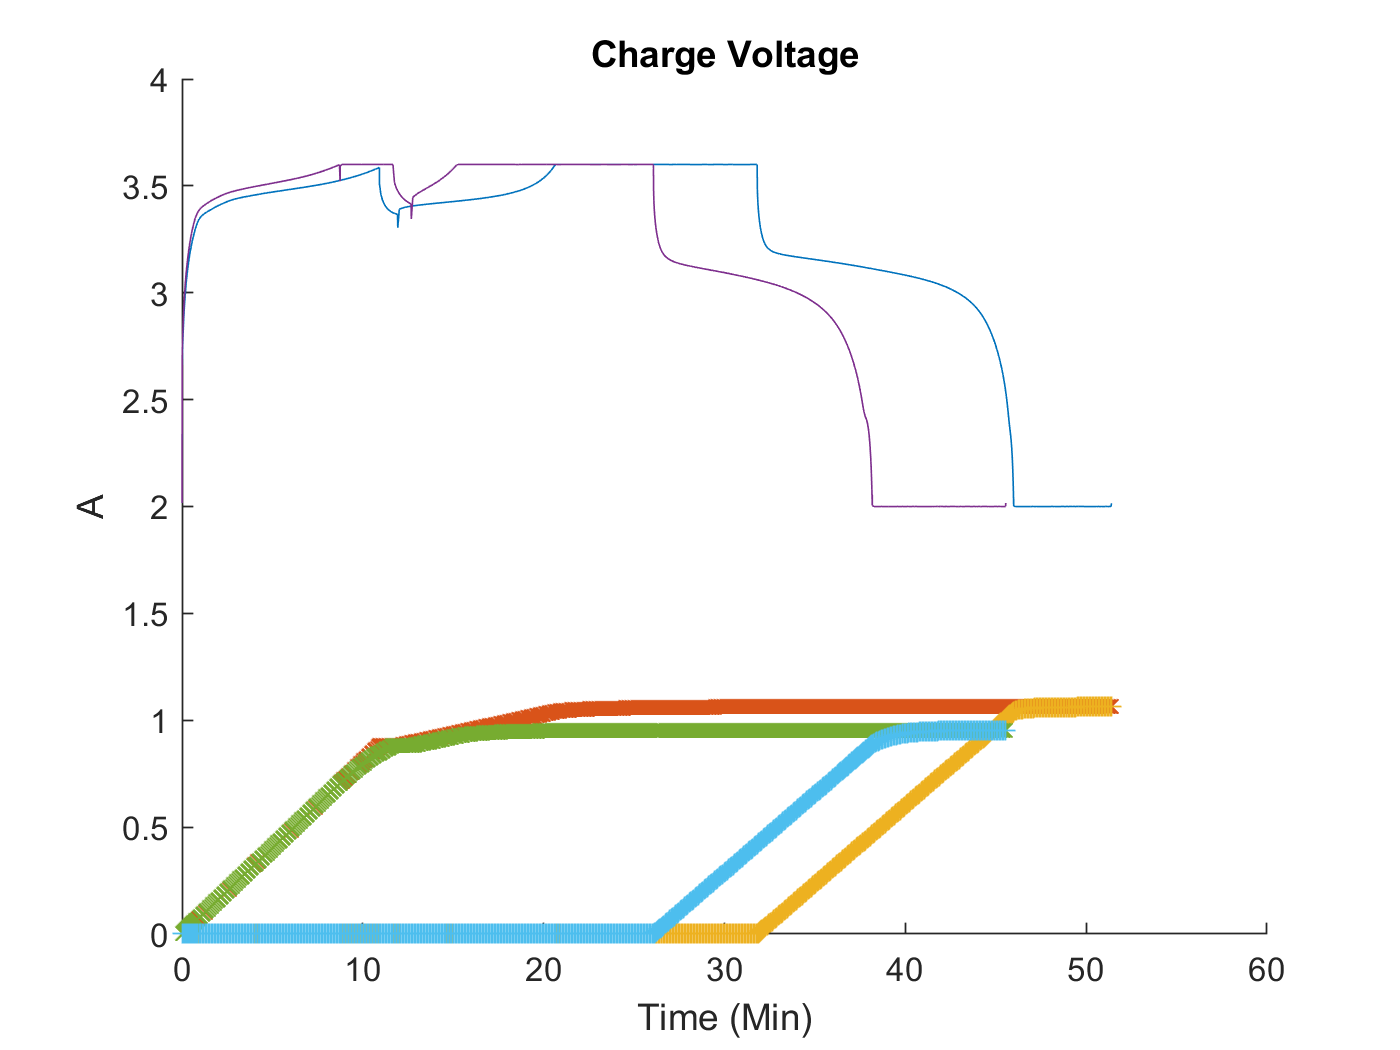

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).V)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Voltage'

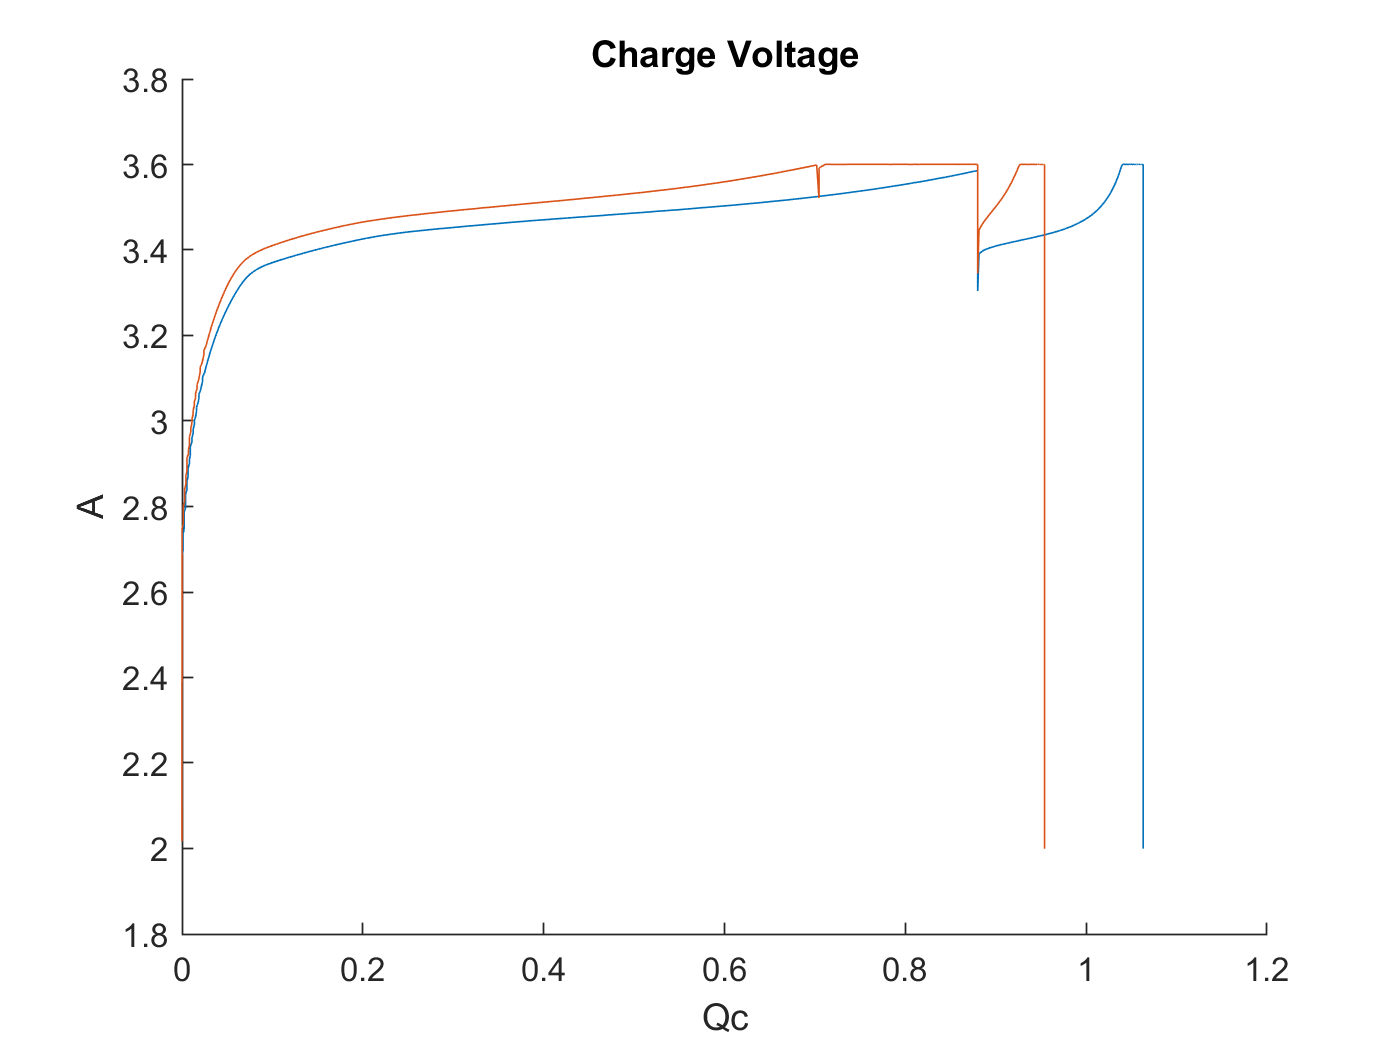


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).V)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Voltage'

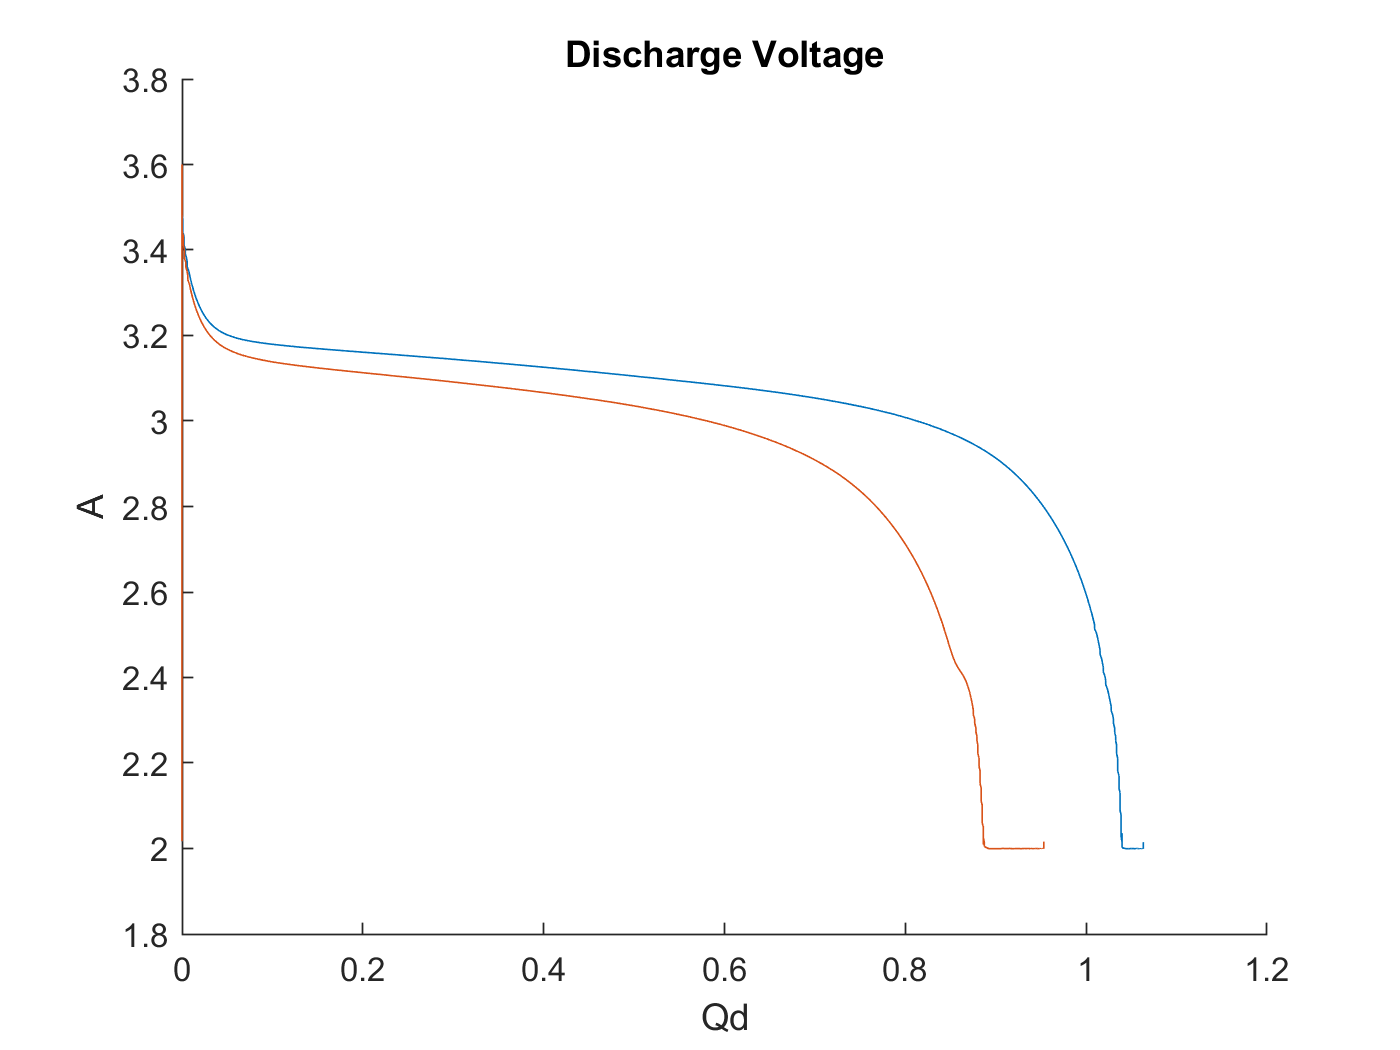


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).V)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Voltage'

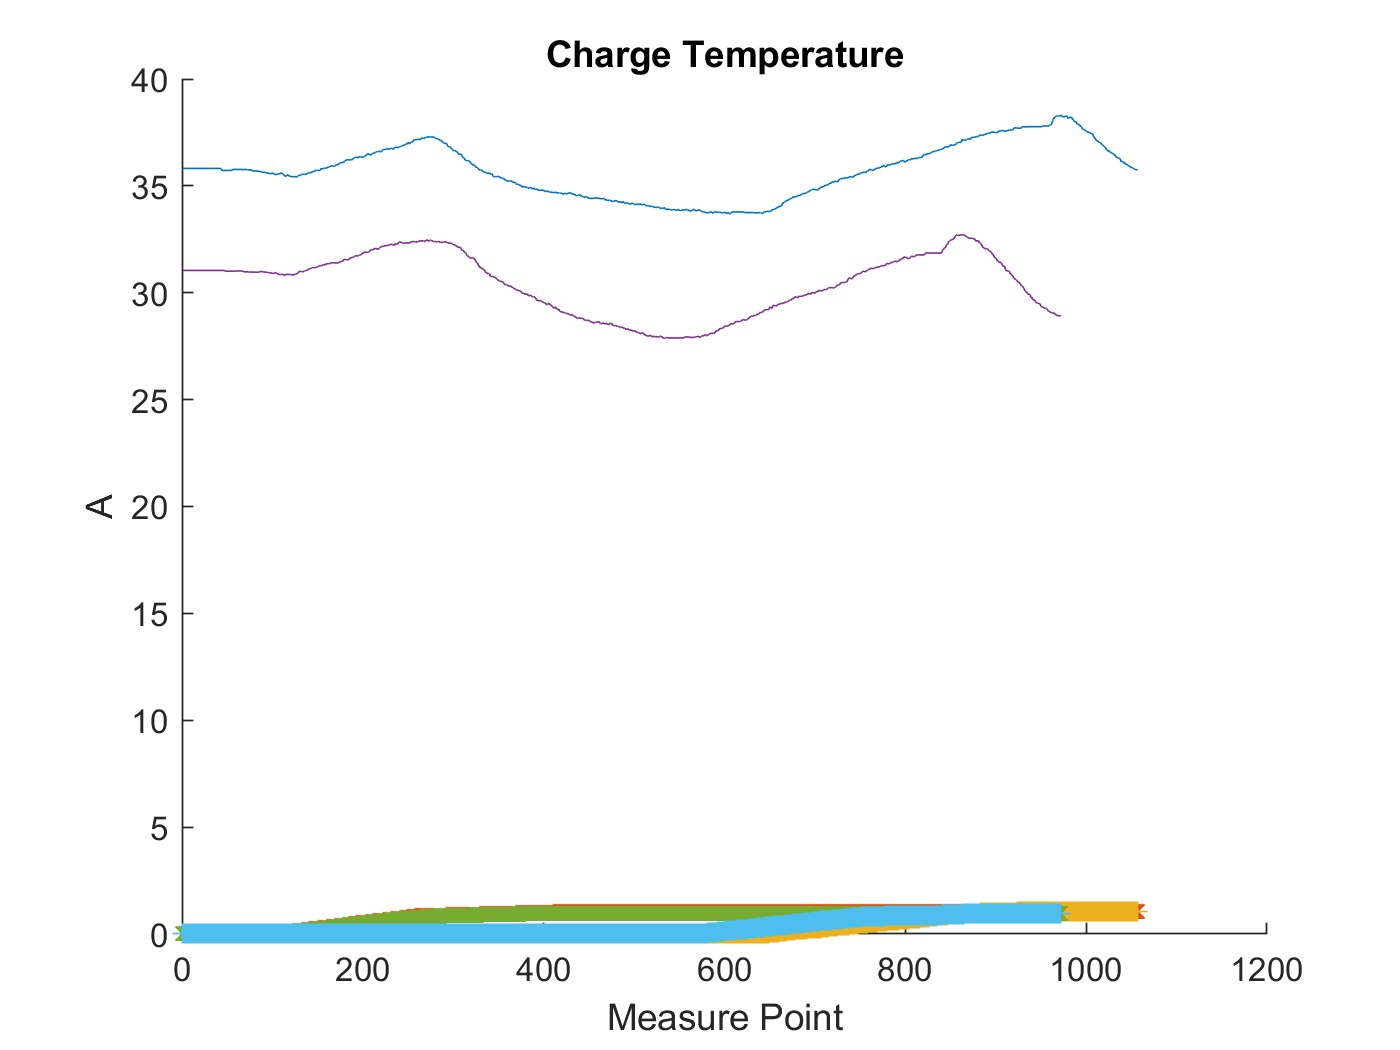

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).T)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Temperature'

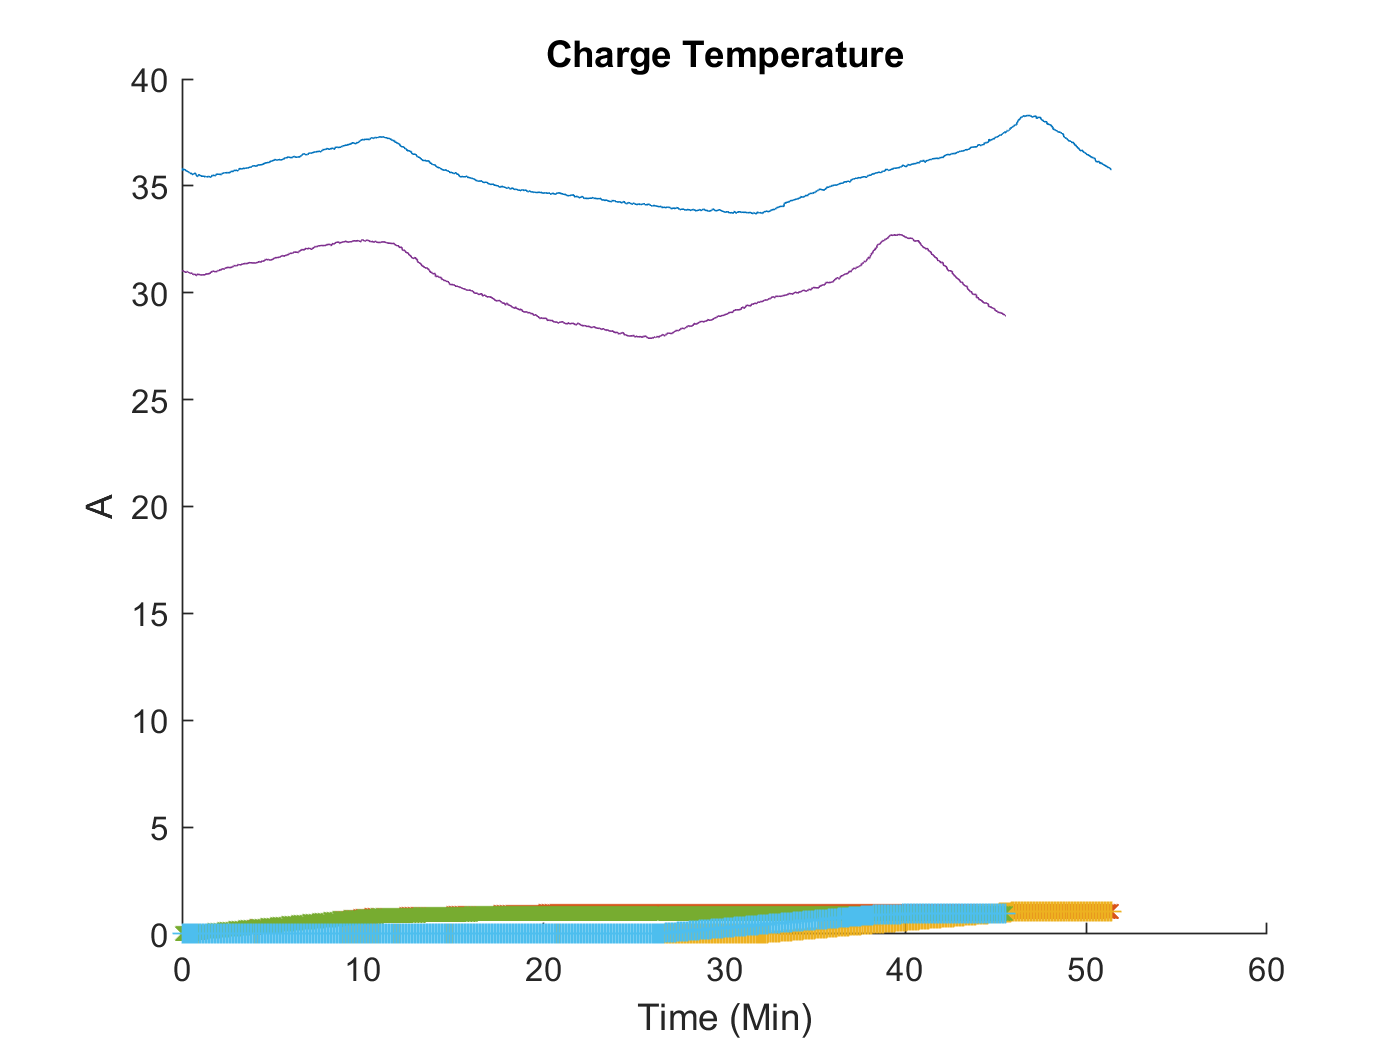

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).T)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Temperature'

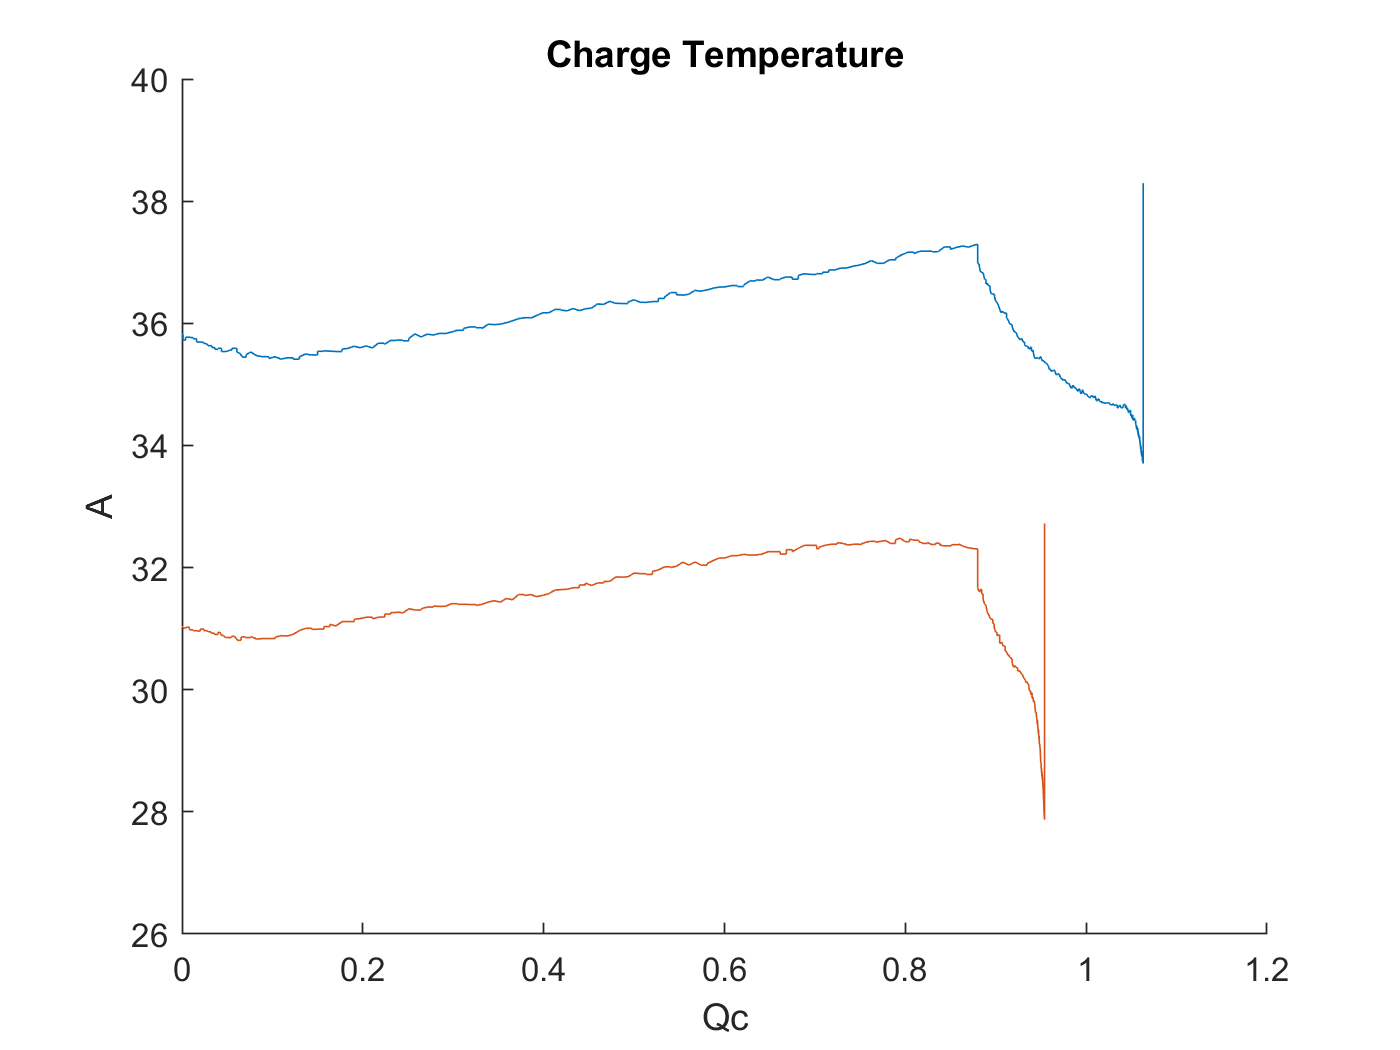


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).T)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Temperature'

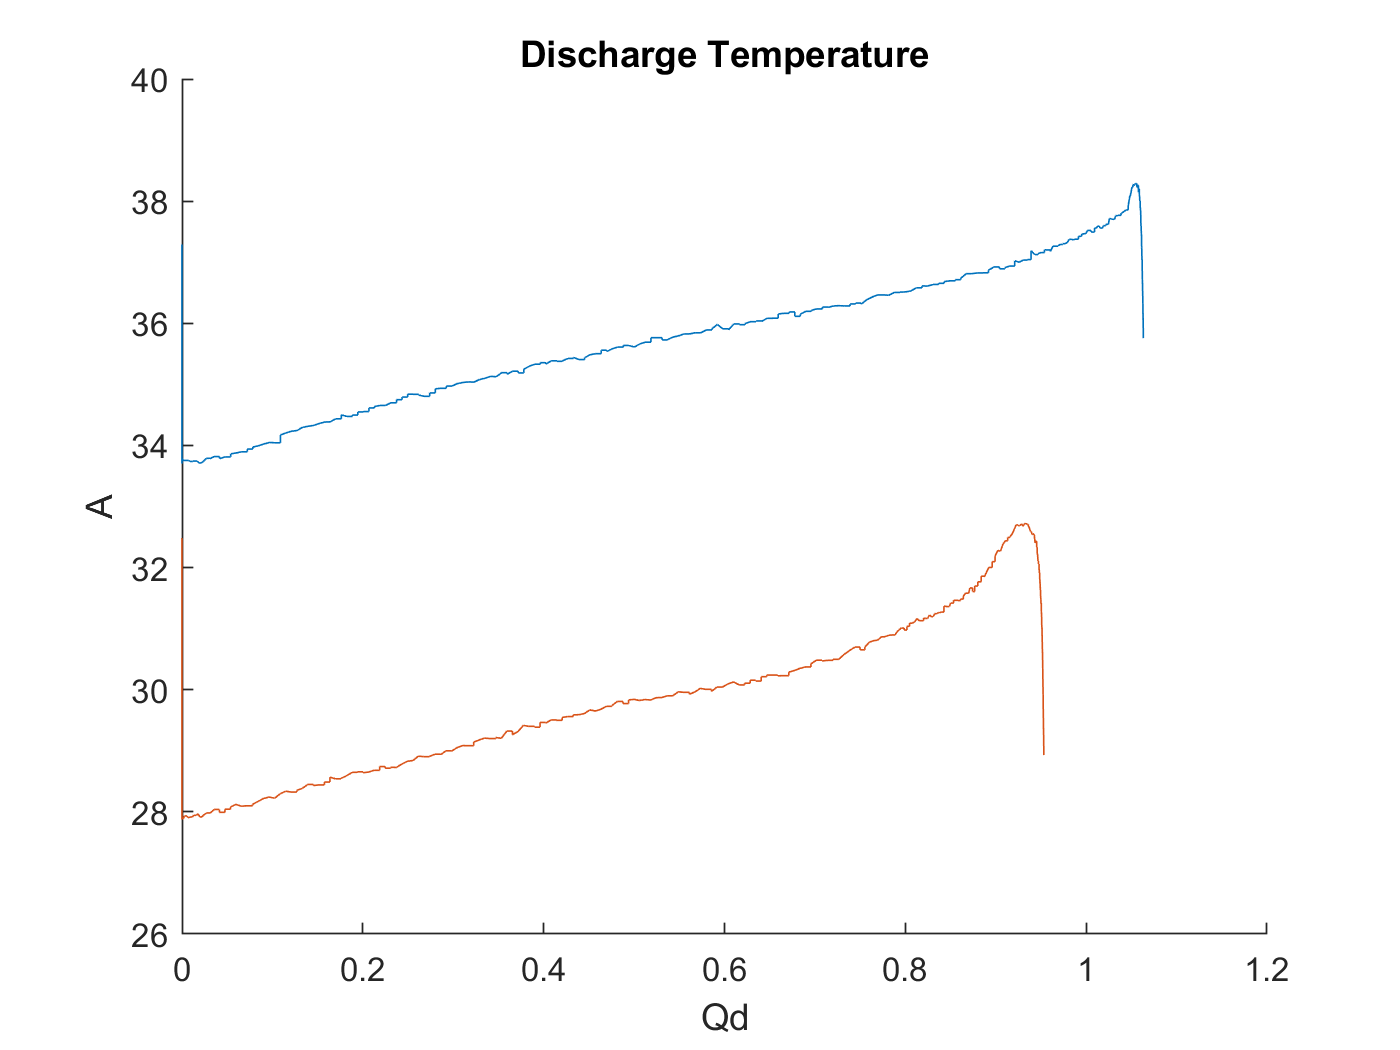


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).T)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Temperature'

데이타중 첫번째 batch에서 하나를 선택해서 데이타 확인



%batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"]
%batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"]
% src = trainData(1); % src has invaild item on index 1
% dest = trainData2(8); % dest has vaild item on index 1
% merge = merge_struct(trainData(1),trainData2(8));

src = trainData(1); % src has invaild item on index 1
dest = trainData2(8); % dest has vaild item on index 1

특정데이타는 다른 batch에 나눠져 있는 경우가 있어서 이를 합쳐야 한다.

merge = merge_struct(trainData(1),trainData2(8));

% verify
src.cycle_life

ans = 1190

dest.cycle_life

ans = 663

src.cycle_life + dest.cycle_life - 1

ans = 1852

merge.cycle_life

ans = 1852

length(src.summary.QDischarge)

ans = 1189

length(dest.summary.QDischarge)

ans = 662

length(merge.summary.QDischarge)

ans = 1851

%%%%%%%%%%%
src.summary.QDischarge(1)

ans = 0

src.summary.QDischarge(2)

ans = 1.0707

src.summary.QDischarge(end-1)

ans = 1.0267

src.summary.QDischarge(end)

ans = 1.0262

%%%%
dest.summary.QDischarge(1)

ans = 1.0219

dest.summary.QDischarge(2)

ans = 1.0233

dest.summary.QDischarge(end-1)

ans = 0.8843

dest.summary.QDischarge(end)

ans = 0.8828

%%%%
merge.summary.QDischarge(1)

ans = 0

merge.summary.QDischarge(2)

ans = 1.0707

merge.summary.QDischarge(length(src.summary.QDischarge)-1)

ans = 1.0267

merge.summary.QDischarge(length(src.summary.QDischarge))

ans = 1.0262

merge.summary.QDischarge(length(src.summary.QDischarge)+1)

ans = 1.0219

merge.summary.QDischarge(length(src.summary.QDischarge)+2)

ans = 1.0233

merge.summary.QDischarge(end-1)

ans = 0.8843

merge.summary.QDischarge(end)

ans = 0.8828

test = zeros();
test = extract_feature_all_new_bat_soc_v4(1,1,merge);

#batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))

batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))

#remove batteries that do not reach 80% capacity

del batch1['b1c8']

del batch1['b1c10']

del batch1['b1c12']

del batch1['b1c13']

del batch1['b1c22']

///////////

# There are four cells from batch1 that carried into batch2, we'll remove the data from batch2

# and put it with the correct cell from batch1

batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']

batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']

add_len = [662, 981, 1060, 208, 482];

for i, bk in enumerate(batch1_keys):

    batch1[bk]['cycle_life'] = batch1[bk]['cycle_life'] + add_len[i]

    for j in batch1[bk]['summary'].keys():

        if j == 'cycle':

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j] + len(batch1[bk]['summary'][j])))

        else:

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j]))

    last_cycle = len(batch1[bk]['cycles'].keys())

    for j, jk in enumerate(batch2[batch2_keys[i]]['cycles'].keys()):

        batch1[bk]['cycles'][str(last_cycle + j)] = batch2[batch2_keys[i]]['cycles'][jk]

del batch2['b2c7']

del batch2['b2c8']

del batch2['b2c9']

del batch2['b2c15']

del batch2['b2c16']

new_index = 1;
battery_dataset_v1 = zeros();
% 이 코드가 중요함. battery_dataset_v1 이 structure를 가짐을 알려주어야 함.
battery_dataset_v1 = extract_feature_all_new_bat_soc_v4(1,1,trainData(1));



% 1.1 * 0.8 = 0.88 Ah = EOL
% batch 2 = get data under 0.88 Ah - to remove this data under EOL
test2 = extract_feature_all_new_bat_soc_v4(2,1,trainData2(1));
test1 = extract_feature_all_new_bat_soc_v4(1,1,trainData(1));
test3 = extract_feature_all_new_bat_soc_v4(3,1,trainData3(1));
skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

% # There are four cells from batch1 that carried into batch2, we'll remove the data from batch2
% # and put it with the correct cell from batch1
% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

skip_bat2 = [7 8 9 15 16 ]; % base 0 index
skip_bat2 = skip_bat2 +1; % to 1 index

batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"];
batch2_fix = [8 9 10 16 17];
batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"];
batch1_fix = [1 2 3 4 5];

batchNum =1;
for batNum = 1:size(trainData,2)
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if ismember(batNum,skip_bat1) 
            batNum;
        elseif ismember(batNum,batch1_fix) 
            %ismember(batNum,batch1_fix) % true or fale
            idx = find(batch1_fix==batNum);
            % find(strcmp
%             batch1_fix(idx)
%             batch2_fix(idx)
            src = trainData(batch1_fix(idx));
            dest = trainData2(batch2_fix(idx));
            merge = merge_struct(trainData(batch1_fix(idx)),trainData2(batch2_fix(idx)));
            battery_dataset_v1(new_index) = extract_feature_all_new_bat_soc_v4(batchNum,batNum,merge);
            batNum;      
        else
            battery_dataset_v1(new_index) = extract_feature_all_new_bat_soc_v4(batchNum,batNum,trainData(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

%%%%%%%%%%%%%
batchNum = 2;
for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if ismember(batNum,batch2_fix) 
            batNum;
        else
            battery_dataset_v1(new_index) = extract_feature_all_new_bat_soc_v4(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end


%%%%%%%%%%%%%%%
batchNum = 3;
skip_bat3 = [37 2 23 32 42 43 ]; % base 0 index
skip_bat3 = skip_bat3 +1; % to 1 index

% # remove noisy channels from batch3
% del batch3['b3c37']
% del batch3['b3c2']
% del batch3['b3c23']
% del batch3['b3c32']
% del batch3['b3c42']
% del batch3['b3c43']

for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        if ismember(batNum,skip_bat3) 
            batNum;
        else
            battery_dataset_v1(new_index) = extract_feature_all_new_bat_soc_v4(batchNum,batNum,trainData3(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

data_conversion_param = zeros();
data_conversion_param = [0 0 0 0 0 0];

idx = idxAll

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


i=1 

i = 1

j = idx(i)

j = 1

battery_dataset_v1(i).QDischargeSmooth(1) 

ans = 1.0795



battery_dataset = zeros()

battery_dataset = 0

battery_dataset = battery_dataset_v1(1)

battery_dataset = struct with fields:
               policy: '4_4C-80PER_4_4C'
      policy_readable: '4.4C(80%)-4.4C'
           channel_id: "7"
           cycle_life: 1072
                  key: "b1c6"
             batchNum: 1
               batNum: 6
           chargetime: [1072×1 double]
                cycle: [1072×1 double]
                   IR: [1072×1 double]
              QCharge: [1072×1 double]
           QDischarge: [1072×1 double]
                 Tavg: [1072×1 double]
                 Tmin: [1072×1 double]
                 Tmax: [1072×1 double]
                Vdlin: [1000×1 double]
                   Vc: [1072×100 double]
                   Tc: [1072×100 double]
                   Vd: [1072×100 double]
                   Td: [1072×100 double]
              VT_leng: 100
                   Ic: [1072×100 double]
                   Id: [1072×100 double]
     QDischargeSmooth: [1072×1 double]
    QDischargePolyMdl: [-9.6874e-13 1.6385e-09 -9.4860e-07 1.5422e-04 1.0742]
    Q

i=1;
for ii = 1:1000
    if battery_dataset_v1(i).QDischargeSmooth(ii) <= 1.048
        % skip count 
        break
    end
end
ii

ii = 644

battery_dataset(i) = battery_dataset_v1(i);
battery_dataset(i).cycle_life = battery_dataset_v1(i).cycle_life - ii;
battery_dataset_v1(i).cycle_life

ans = 1072

battery_dataset(i).cycle_life

ans = 428

battery_dataset(i).chargetime([1:ii],:) = [] ;

size(battery_dataset_v1(i).chargetime)

ans =         1072           1


size(battery_dataset(i).chargetime)

ans =    428     1


battery_dataset(i).cycle = [] ;
battery_dataset(i).cycle = battery_dataset_v1(i).cycle(1:end-ii,:);
battery_dataset(i).IR([1:ii],:) = [] ;
battery_dataset(i).QCharge([1:ii],:) = [] ;
battery_dataset(i).QDischarge([1:ii],:) = [] ;
battery_dataset(i).Tavg([1:ii],:) = [] ;
battery_dataset(i).Tmin([1:ii],:) = [] ;
battery_dataset(i).Tmax([1:ii],:) = [] ;
battery_dataset(i).Vc([1:ii],:) = [] ;
battery_dataset(i).Vd([1:ii],:) = [] ;
battery_dataset(i).Tc([1:ii],:) = [] ;
battery_dataset(i).Td([1:ii],:) = [] ;
battery_dataset(i).Ic([1:ii],:) = [] ;
battery_dataset(i).Id([1:ii],:) = [] ;
battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
battery_dataset(i).QDischargePolyMdl = [];
battery_dataset(i).QDischargePolyMdl = polyfit(battery_dataset(i).cycle, battery_dataset(i).QDischargeSmooth,4);
battery_dataset(i).QDischargePolyfit = [];
battery_dataset(i).QDischargePolyfit = polyval(battery_dataset.QDischargePolyMdl,battery_dataset.cycle')';

%%%%%%%%%%%%%%%%%%
% get first capacity
for i = 1:length(idx)
    %j = idx(i);
    initC = battery_dataset_v1(i).QDischargeSmooth(1) ;

    for ii = 1:battery_dataset_v1(i).cycle_life
        if battery_dataset_v1(i).QDischargeSmooth(ii) <= 1.048
            % skip count 
            break
        end
        if ii == battery_dataset_v1(i).cycle_life
            error_is = true;
        end
    end
    %              bat_num        new_start_index  
    
    battery_dataset(i) = battery_dataset_v1(i);
    battery_dataset(i).cycle_life = battery_dataset_v1(i).cycle_life - ii;
    %battery_dataset_v1(i).cycle_life
    %battery_dataset(i).cycle_life
    battery_dataset(i).chargetime([1:ii],:) = [] ;

    data_conversion_param(i,:) = [ i      initC  ii   battery_dataset_v1(i).QDischargeSmooth(ii)   battery_dataset_v1(i).cycle_life battery_dataset(i).cycle_life    ];
    
    %size(battery_dataset_v1(i).chargetime)
    %size(battery_dataset(i).chargetime)
    battery_dataset(i).cycle = [] ;
    battery_dataset(i).cycle = battery_dataset_v1(i).cycle(1:end-ii,:);
    battery_dataset(i).IR([1:ii],:) = [] ;
    battery_dataset(i).QCharge([1:ii],:) = [] ;
    battery_dataset(i).QDischarge([1:ii],:) = [] ;
    battery_dataset(i).Tavg([1:ii],:) = [] ;
    battery_dataset(i).Tmin([1:ii],:) = [] ;
    battery_dataset(i).Tmax([1:ii],:) = [] ;
    battery_dataset(i).Vc([1:ii],:) = [] ;
    battery_dataset(i).Vd([1:ii],:) = [] ;
    battery_dataset(i).Ic([1:ii],:) = [] ;
    battery_dataset(i).Id([1:ii],:) = [] ;    
    battery_dataset(i).Tc([1:ii],:) = [] ;
    battery_dataset(i).Td([1:ii],:) = [] ;
    battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
    battery_dataset(i).QDischargePolyMdl = [];
    battery_dataset(i).QDischargePolyMdl = polyfit(battery_dataset(i).cycle, battery_dataset(i).QDischargeSmooth,4);
    battery_dataset(i).QDischargePolyfit = [];
    battery_dataset(i).QDischargePolyfit = polyval(battery_dataset(i).QDischargePolyMdl,battery_dataset(i).cycle')';


end
data_conversion_param 

data_conversion_param = 	1.0e+03 *

    0.0010    0.0011    0.6440    0.0010    1.0720    0.4280
    0.0020    0.0011    0.4050    0.0010    0.6340    0.2290
    0.0030    0.0011    0.6150    0.0010    0.8680    0.2530
    0.0040    0.0011    0.7140    0.0010    1.0520    0.3380
    0.0050    0.0011    0.3700    0.0010    0.7860    0.4160
    0.0060    0.0011    0.5470    0.0010    0.8780    0.3310
    0.0070    0.0011    0.4390    0.0010    0.7170    0.2780
    0.0080    0.0011    0.6250    0.0010    0.8600    0.2350
    0.0090    0.0011    0.5710    0.0010    0.8550    0.2840
    0.0100    0.0011    0.2270    0.0010    0.6890    0.4620


max(data_conversion_param(:,2))

ans = 1.0982

min(data_conversion_param(:,2))

ans = 1.0480

length(battery_dataset)
size(battery_dataset)
[battery_dataset.key]
{[battery_dataset.key]}
contains([battery_dataset.key],'b1','IgnoreCase',true)
contains([battery_dataset.key],'b2','IgnoreCase',true)
contains([battery_dataset.key],'b3','IgnoreCase',true)
idx1 = find(contains([battery_dataset.key],'b1','IgnoreCase',true))
idx2 = find(contains([battery_dataset.key],'b2','IgnoreCase',true))
idx3 = find(contains([battery_dataset.key],'b3','IgnoreCase',true))
idx12 = [idx1 idx2]
idx13 = [idx1 idx3]
idx23 = [idx2 idx3]
idxAll = (1:length(battery_dataset))
idx123 = [idx1 idx2 idx3]

key1 = [battery_dataset(idx1).key]'
key2 = [battery_dataset(idx2).key]'
key3 = [battery_dataset(idx3).key]'

cycle_life = [battery_dataset(idxAll).cycle_life]'

cycle_life =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


bat_index = [1:length(idxAll)]'

bat_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


index_cyclelife = [ bat_index, cycle_life]

index_cyclelife =      1   428
     2   229
     3   253
     4   338
     5   416
     6   331
     7   278
     8   235
     9   284
    10   462


% https://kr.mathworks.com/help/matlab/ref/double.sortrows.html#bt8bz9j-3
index_cyclelife_table = table(bat_index,cycle_life)

index_cyclelife_table = 119×2 table
    bat_index    cycle_life
    _________    __________

        1           428    
        2           229    
        3           253    
        4           338    
        5           416    
        6           331    
        7           278    
        8           235    
        9           284    
       10           462    
       11           269    
       12           379    
       13           300    
       14           354    
       15           405    
       16           316    


[index_cyclelife_table_sort,index] = sortrows(index_cyclelife_table,{'cycle_life'},{'ascend'})

index_cyclelife_table_sort = 119×2 table
    bat_index    cycle_life
    _________    __________

       38           109    
       78           115    
       71           118    
       69           129    
       65           137    
       76           140    
       61           146    
       74           146    
       73           152    
       66           153    
       70           153    
       64           154    
       68           155    
       75           157    
       63           161    
       48           168    


index =     38
    78
    71
    69
    65
    76
    61
    74
    73
    66



%%%%%%%%%%%%%%%%
total_index = length(idxAll)

total_index = 119

	
index_cyclelife_table_sort.Variables

ans =     38   109
    78   115
    71   118
    69   129
    65   137
    76   140
    61   146
    74   146
    73   152
    66   153


index_cyclelife_table_sort.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'bat_index'  'cycle_life'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


[~, maxrow] = max(index_cyclelife_table_sort.bat_index)

maxrow = 116

%maxrowname = index_cyclelife_table_sort.Properties.RowNames(1:maxrow-1)
%index_cyclelife_table_sort.Properties.RowNames

index_vec = [1:total_index]

index_vec =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxVal_ = index_vec(5:10:end)

idxVal_ =      5    15    25    35    45    55    65    75    85    95   105   115


idxTest_ = index_vec(6:10:end)

idxTest_ =      6    16    26    36    46    56    66    76    86    96   106   116


idxTrain_ = setdiff(index_vec,idxVal_);
idxTrain_ = setdiff(idxTrain_,idxTest_)

idxTrain_ =      1     2     3     4     7     8     9    10    11    12    13    14    17    18    19    20    21    22    23    24    27    28    29    30    31    32    33    34    37    38    39    40    41    42    43    44    47    48    49    50    51    52    53    54    57    58    59    60    61    62


idxTestTable = index_cyclelife_table_sort(idxTest_,{'bat_index'})

idxTestTable = 12×1 table
    bat_index
    _________

        76   
        48   
        62   
        28   
        26   
        47   
        16   
        99   
        92   
       106   
        84   
       119   


idxTrainTable = index_cyclelife_table_sort(idxTrain_,{'bat_index'})

idxTrainTable = 95×1 table
    bat_index
    _________

       38    
       78    
       71    
       69    
       61    
       74    
       73    
       66    
       70    
       64    
       68    
       75    
       52    
       60    
       30    
       36    


idxValTable = index_cyclelife_table_sort(idxVal_,{'bat_index'})

idxValTable = 12×1 table
    bat_index
    _________

        65   
        63   
        56   
        59   
        40   
        11   
        46   
        14   
        94   
        10   
       100   
       115   


idxTest = idxTestTable.Variables'

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


idxValid = idxValTable.Variables'

idxValid =     65    63    56    59    40    11    46    14    94    10   100   115


idxTrain = idxTrainTable.Variables'

idxTrain =     38    78    71    69    61    74    73    66    70    64    68    75    52    60    30    36    39    54    67    77    35    42    72    21    29    37    58    49    24    25    27    33    53     2    22     8    57    23    55    45     3    17    34    41   109    18     7     9    13    93


idxAll

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxTrainSort = sort(idxTrain)

idxTrainSort =      1     2     3     4     5     6     7     8     9    12    13    15    17    18    19    20    21    22    23    24    25    27    29    30    31    32    33    34    35    36    37    38    39    41    42    43    44    45    49    50    51    52    53    54    55    57    58    60    61    64


idxValidSort = sort(idxValid)

idxValidSort =     10    11    14    40    46    56    59    63    65    94   100   115


idxTestSort = sort(idxTest)

idxTestSort =     16    26    28    47    48    62    76    84    92    99   106   119



%https://kr.mathworks.com/matlabcentral/answers/101996-how-can-i-sort-a-vector-in-a-random-manner-in-matlab

idxTestRand =  idxTest(randperm(length(idxTest)))

idxTestRand =     26   106    28    76   119    84    47    62    92    16    48    99


idxTrainRand =  idxTrain(randperm(length(idxTrain)))

idxTrainRand =     35    38    75     1     2    13    77     6    30    53    90   103   102   101    42    12    20    69    22    73    49   113     8     7    32   114    74    15    70    29    88    78    95    51    86    33    91   116    31    55    85    23    61    43    60    89   112    97    34    82


idxValidRand =  idxValid(randperm(length(idxValid)))

idxValidRand =     94    63   100    46   115    65    10    14    11    40    56    59



%sortrows(idxValTable,{'cycle_life'},{'ascend'})
input_size = 100;

ryan3_gen_data_desc = 'ryan3_gen_data';
save('ryan3_gen_data.mat','ryan3_gen_data_desc');
save('ryan3_gen_data.mat','battery_dataset' ,'-append')
% battery_dataset_v1 는 지워도 된다.
%save('ryan3_gen_data.mat','battery_dataset_v1' ,'-append')
save('ryan3_gen_data.mat','data_conversion_param' ,'-append')
save('ryan3_gen_data.mat','idx1' ,'-append')
save('ryan3_gen_data.mat','idx2' ,'-append')
save('ryan3_gen_data.mat','idx3' ,'-append')
save('ryan3_gen_data.mat','idx12' ,'-append')
save('ryan3_gen_data.mat','idx23' ,'-append')
save('ryan3_gen_data.mat','idx13' ,'-append')
save('ryan3_gen_data.mat','idxAll' ,'-append')
save('ryan3_gen_data.mat','idx123' ,'-append')
save('ryan3_gen_data.mat','key1' ,'-append')
save('ryan3_gen_data.mat','key2' ,'-append')
save('ryan3_gen_data.mat','key3' ,'-append')
save('ryan3_gen_data.mat','input_size' ,'-append')

save('ryan3_gen_data.mat','idxTrain' ,'-append')
save('ryan3_gen_data.mat','idxValid' ,'-append')
save('ryan3_gen_data.mat','idxTest' ,'-append')
save('ryan3_gen_data.mat','idxTrainRand' ,'-append')
save('ryan3_gen_data.mat','idxValidRand' ,'-append')
save('ryan3_gen_data.mat','idxTestRand' ,'-append')
save('ryan3_gen_data.mat','idxTrainSort' ,'-append')
save('ryan3_gen_data.mat','idxValidSort' ,'-append')
save('ryan3_gen_data.mat','idxTestSort' ,'-append')
